# Problem 2: Aerobraking

Student 1: Álvaro Reviriego Moreno 

Student 2: Enrique Sentana Gómez

Data of the problem:

clear all;
mu = 42828.4;                       % mu Mars [km^3/s^2] 
RM = 3389.9;                        % Radius of Mars [km]

a = 5940;                           % Semi-major axis [km]
e= 0.4;                             % Eccentricity 
Omega = deg2rad(194);               % RAAN 
i = deg2rad(56);                    % Inclination 
omega = deg2rad(258);               % Argument of periapsis 

theta_0 = deg2rad(230);             % True anomaly at t=0 
S = 10;                             % Shield area [m^2]
m = 3000;                           % Mass of the spacecraft [kg]


## Initial position and velocity vectors

The goal of this second problem related to aerobraking consist on analyzing the effect of the atmospheric drag on the evolution of the orbit of a determined body. In order to do the described task, the first step is to compute the initial state vector $X = [\vec{r},\vec{v}]$ from the given COEs. In order to do this, the function `coe2stat.m `is used. 

X_init = coe2stat([a,e,i,Omega,omega,theta_0],mu)       % Initial state vector 

X_init = 1.0e+03 *

    4.7283
   -1.8713
    4.3878
    0.0009
    0.0014
   -0.0017


## Ideal 2BP Cowell propagation and convergence study

This section is devoted to analyze the propagation returned from a numerical integrator for different values of $\delta t$. The values selected for the time-step are $\delta t = [300, 150, 75, 37.5] s$. The method used to calculate the propagation of the orbit 'Runge-Kutta $4^{th}$ order' (RK4) integrator. 

Runge-Kutta methods are a set of implicit and explicit iterative methods of numerical resolution of ordinary differential ecuations (ODE). If we define an initial value problem (IVP)

 $y' = f(x,t)$, with $y(x_0) = y_0$

The following RK4 steps is implemented by the following scheme


$$y_{i+1} = y_{i} + \frac{1}{6}h(k_{1} + 2k_{2}+2k_{3}+k_{4})$$


where $h $ is the time step and k are the intermediate coefficients, given by the following set of equations 


$$
k_{1} = f(x_{i},y_{i}) \\
k_{2} = f(x_{i}+ \frac{1}{2}h, y_{i}+ \frac{1}{2}hk_{1})\\
k_{3} = f(x_{i}+ \frac{1}{2}h, y_{i}+ \frac{1}{2}hk_{2}) \\
k_{4} = f(x_{i}+h, y_{i}+hk_{3})
$$


As we can see above, in order to implement the RK4 method, we must define clearly the set of ODEs that governs the orbit of the body. There are many ways to define the differential equations governing the propagation of the orbit, but in this task Cowell's formulation is used. Cowell's formulation consist on adding to the gravitational acceleration of the body (the one with no perturbation) the acceleration due to the atmospheric drag, which can be defined as 


$$\vec{a_{P}} = -\frac{1}{2\cdot B_{c}} \cdot  \rho\cdot v\cdot \vec{v} = -\frac{1}{2} \frac{C_{D}S}{m_{P}} \cdot \rho\cdot v\cdot \vec{v}$$


This acceleration due to the drag is calculated in the function `drag_acceleration.m`. We must also note that the density of the atmosphere ($\rho$) is calculated in the function `Mars_atmosphere.m`. In this function...(**Explicar mars atmosphere cuando este bien**) 

Once the perturbation acceleration is calculated, we can pose the Cowell's formulation of the 2-Body perturbed problem, implemented in the `Cowell.m `function


$$\frac{\mathrm{d^2} \vec{r}}{\mathrm{d} t^2} = - \frac{\mu}{r^3}\vec{r} + \vec{a_{P}}$$


The mentioned `Cowell.m `function is the one introduced in the RK4 integrator to propagate the orbit in time. Note that in the implemented function `RK4.m`, we define a flag as input. This flag is set to true if we want to compute the perurbed orbit, and set to false if we do not want to, leading to $\vec{a_{P}} = 0$. The goal of this section consist on analyzing the orbit with no perturbations, so the flag is set to false. 

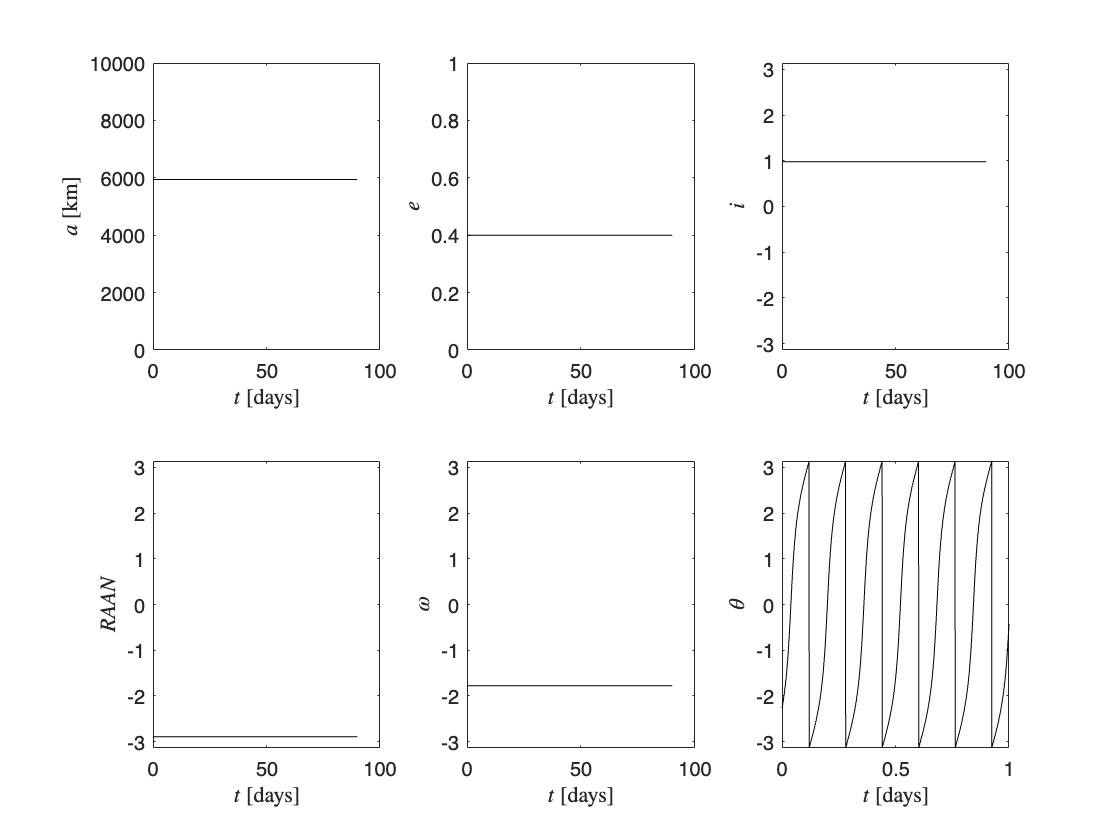

flag = false;
tf = 90*24*3600;

dt1 = 300;
t1 = 0:dt1:tf;
X1 = RK4(X_init,dt1,flag);

for j =1:length(X1)
    coe1(:,j) = stat2coe(X1(:,j),mu); 
end


figure(1)
plot_orbit(t1,coe1)

dt2 = 150; 
t2 = 0:dt2:tf;
X2 = RK4(X_init,dt2,flag);

for j =1:length(X2)
    coe2(:,j) = stat2coe(X2(:,j),mu); 
end

figure(2)
plot_orbit(t2,coe2)

dt3 = 75;
t3 = 0:dt3:tf; 
X3 = RK4(X_init,dt3,flag);

for j =1:length(X3)
    coe3(:,j) = stat2coe(X3(:,j),mu); 
end

figure(3)
plot_orbit(t3,coe3)

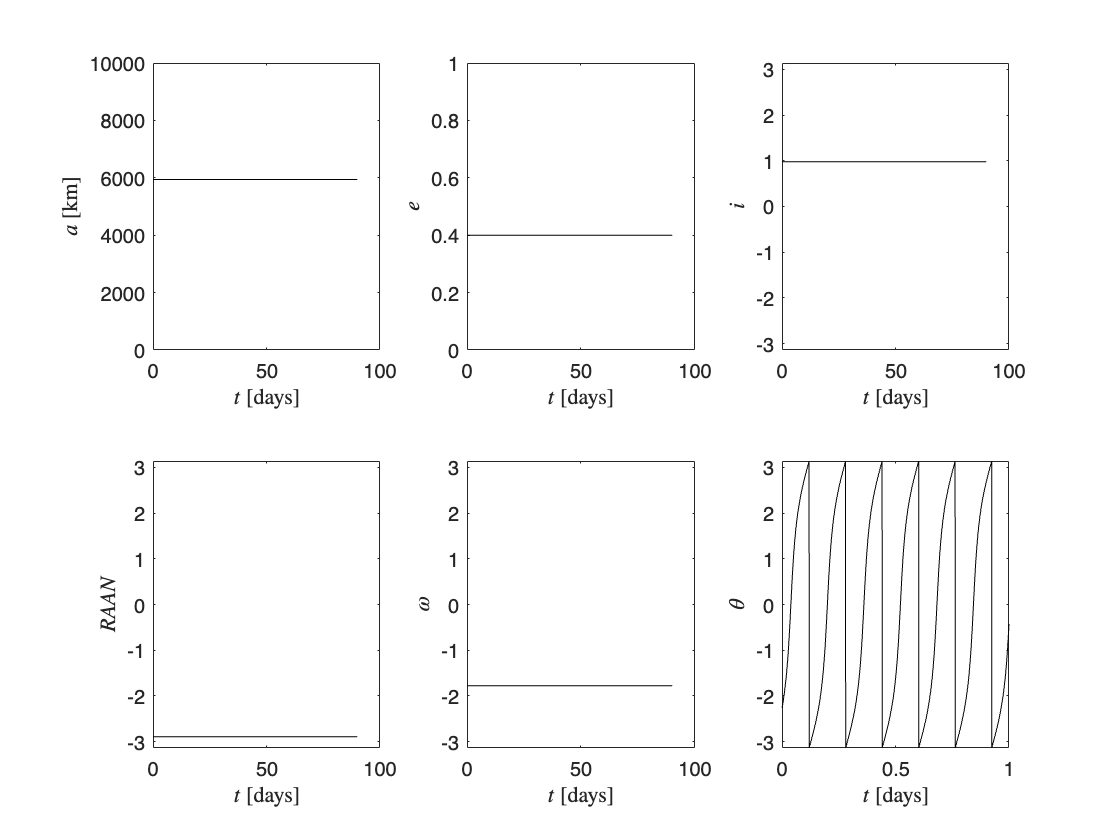


dt4 = 37.5;
t4 = 0:dt4:tf;
X4 = RK4(X_init,dt4,flag);

for j =1:length(X4)
    coe4(:,j) = stat2coe(X4(:,j),mu); 
end

figure(4)
plot_orbit(t4,coe4)

And you can add more code/text blocks as needed.

## Perturbed 2BP Cowell propagation

This section is devoted to analyze the propagation of the orbit under the effect of the perturbation due to drag acceleration. In this case, the formulation is the same as in the previous section, with the main difference that now $\vec{a_{P} \neq 0$, so the flag is set to true. Moreover, we must note that in this section the time step used is $\delta t_{4} = 37.5 s$.

X4_2 = RK4(X_init,dt4,true);

a_p = 1.0e-218 *

   -0.3464
   -0.5668
    0.6911


a_p = 1.0e-217 *

   -0.4318
   -0.7196
    0.8802


a_p = 1.0e-217 *

   -0.4541
   -0.7569
    0.9259


a_p = 1.0e-218 *

   -0.3464
   -0.5668
    0.6911


a_p = 1.0e-217 *

   -0.4318
   -0.7196
    0.8802


a_p = 1.0e-217 *

   -0.4541
   -0.7569
    0.9259


a_p = 1.0e-215 *

   -0.0573
   -0.0974
    0.1195


a_p = 1.0e-215 *

   -0.0573
   -0.0974
    0.1195


a_p = 1.0e-214 *

   -0.0733
   -0.1268
    0.1561


a_p = 1.0e-214 *

   -0.0771
   -0.1335
    0.1643


a_p = 1.0e-215 *

   -0.0573
   -0.0974
    0.1195


a_p = 1.0e-214 *

   -0.0733
   -0.1268
    0.1561


a_p = 1.0e-214 *

   -0.0771
   -0.1335
    0.1643


a_p = 1.0e-213 *

   -0.0998
   -0.1761
    0.2176


a_p = 1.0e-213 *

   -0.0998
   -0.1761
    0.2176


a_p = 1.0e-212 *

   -0.1307
   -0.2353
    0.2916


a_p = 1.0e-212 *

   -0.1376
   -0.2478
    0.3071


a_p = 1.0e-213 *

   -0.0998
   -0.1761
    0.2176


a_p = 1.0e-212 *

   -0.1307
   -0.2353
    0.2916


a_p = 1.0e-212 *

   -0.1376
   -0.2478
    0.3071


a_p = 1.0e-211 *

   -0.1825
   -0.3354
    0.4171


a_p = 1.0e-211 *

   -0.1825
   -0.3354
    0.4170


a_p = 1.0e-210 *

   -0.2449
   -0.4596
    0.5734


a_p = 1.0e-210 *

   -0.2580
   -0.4843
    0.6041


a_p = 1.0e-211 *

   -0.1825
   -0.3354
    0.4170


a_p = 1.0e-210 *

   -0.2449
   -0.4596
    0.5734


a_p = 1.0e-210 *

   -0.2580
   -0.4843
    0.6041


a_p = 1.0e-209 *

   -0.3507
   -0.6724
    0.8415


a_p = 1.0e-209 *

   -0.3506
   -0.6723
    0.8413


a_p = 1.0e-207 *

   -0.0482
   -0.0945
    0.1186


a_p = 1.0e-207 *

   -0.0508
   -0.0996
    0.1251


a_p = 1.0e-209 *

   -0.3506
   -0.6723
    0.8413


a_p = 1.0e-207 *

   -0.0482
   -0.0945
    0.1186


a_p = 1.0e-207 *

   -0.0508
   -0.0996
    0.1251


a_p = 1.0e-206 *

   -0.0708
   -0.1418
    0.1786


a_p = 1.0e-206 *

   -0.0708
   -0.1418
    0.1786


a_p = 1.0e-205 *

   -0.0997
   -0.2043
    0.2582


a_p = 1.0e-205 *

   -0.1051
   -0.2155
    0.2723


a_p = 1.0e-206 *

   -0.0708
   -0.1418
    0.1786


a_p = 1.0e-205 *

   -0.0997
   -0.2043
    0.2582


a_p = 1.0e-205 *

   -0.1051
   -0.2155
    0.2723


a_p = 1.0e-204 *

   -0.1499
   -0.3146
    0.3989


a_p = 1.0e-204 *

   -0.1498
   -0.3146
    0.3988


a_p = 1.0e-203 *

   -0.2161
   -0.4648
    0.5911


a_p = 1.0e-203 *

   -0.2280
   -0.4905
    0.6238


a_p = 1.0e-204 *

   -0.1498
   -0.3146
    0.3988


a_p = 1.0e-203 *

   -0.2161
   -0.4648
    0.5911


a_p = 1.0e-203 *

   -0.2280
   -0.4905
    0.6238


a_p = 1.0e-202 *

   -0.3329
   -0.7340
    0.9365


a_p = 3×1
1.0e-202 *

   -0.3329
   -0.7339
    0.9363


a_p = 3×1
1.0e-200 *

   -0.0491
   -0.1111
    0.1422


a_p = 3×1
1.0e-200 *

   -0.0519
   -0.1174
    0.1502


a_p = 3×1
1.0e-202 *

   -0.3329
   -0.7339
    0.9363


a_p = 3×1
1.0e-200 *

   -0.0491
   -0.1111
    0.1422


a_p = 3×1
1.0e-200 *

   -0.0519
   -0.1174
    0.1502


a_p = 3×1
1.0e-199 *

   -0.0775
   -0.1800
    0.2311


a_p = 3×1
1.0e-199 *

   -0.0775
   -0.1799
    0.2311


a_p = 3×1
1.0e-198 *

   -0.1171
   -0.2793
    0.3597


a_p = 3×1
1.0e-198 *

   -0.1237
   -0.2951
    0.3801


a_p = 3×1
1.0e-199 *

   -0.0775
   -0.1799
    0.2311


a_p = 3×1
1.0e-198 *

   -0.1171
   -0.2793
    0.3597


a_p = 3×1
1.0e-198 *

   -0.1237
   -0.2951
    0.3801


a_p = 3×1
1.0e-197 *

   -0.1891
   -0.4637
    0.5993


a_p = 3×1
1.0e-197 *

   -0.1891
   -0.4636
    0.5991


a_p = 3×1
1.0e-196 *

   -0.2922
   -0.7372
    0.9556


a_p = 3×1
1.0e-195 *

   -0.0309
   -0.0779
    0.1010


a_p = 3×1
1.0e-197 *

   -0.1891
   -0.4636
    0.5991


a_p = 3×1
1.0e-196 *

   -0.2922
   -0.7372
    0.9556


a_p = 3×1
1.0e-195 *

   -0.0309
   -0.0779
    0.1010


a_p = 3×1
1.0e-194 *

   -0.0483
   -0.1255
    0.1632


a_p = 3×1
1.0e-194 *

   -0.0483
   -0.1255
    0.1632


a_p = 3×1
1.0e-193 *

   -0.0763
   -0.2043
    0.2666


a_p = 3×1
1.0e-193 *

   -0.0807
   -0.2162
    0.2820


a_p = 3×1
1.0e-194 *

   -0.0483
   -0.1255
    0.1632


a_p = 3×1
1.0e-193 *

   -0.0763
   -0.2043
    0.2666


a_p = 3×1
1.0e-193 *

   -0.0807
   -0.2162
    0.2820


a_p = 3×1
1.0e-192 *

   -0.1289
   -0.3565
    0.4666


a_p = 3×1
1.0e-192 *

   -0.1288
   -0.3564
    0.4665


a_p = 3×1
1.0e-191 *

   -0.2080
   -0.5944
    0.7804


a_p = 3×1
1.0e-191 *

   -0.2201
   -0.6293
    0.8263


a_p = 3×1
1.0e-192 *

   -0.1288
   -0.3564
    0.4665


a_p = 3×1
1.0e-191 *

   -0.2080
   -0.5944
    0.7804


a_p = 3×1
1.0e-191 *

   -0.2201
   -0.6293
    0.8263


a_p = 3×1
1.0e-189 *

   -0.0359
   -0.1062
    0.1400


a_p = 3×1
1.0e-189 *

   -0.0359
   -0.1062
    0.1399


a_p = 3×1
1.0e-188 *

   -0.0592
   -0.1814
    0.2397


a_p = 3×1
1.0e-188 *

   -0.0627
   -0.1922
    0.2539


a_p = 3×1
1.0e-189 *

   -0.0359
   -0.1062
    0.1399


a_p = 3×1
1.0e-188 *

   -0.0592
   -0.1814
    0.2397


a_p = 3×1
1.0e-188 *

   -0.0627
   -0.1922
    0.2539


a_p = 3×1
1.0e-187 *

   -0.1045
   -0.3321
    0.4403


a_p = 3×1
1.0e-187 *

   -0.1045
   -0.3321
    0.4402


a_p = 3×1
1.0e-186 *

   -0.1757
   -0.5803
    0.7718


a_p = 3×1
1.0e-186 *

   -0.1862
   -0.6152
    0.8182


a_p = 3×1
1.0e-187 *

   -0.1045
   -0.3321
    0.4402


a_p = 3×1
1.0e-186 *

   -0.1757
   -0.5803
    0.7718


a_p = 3×1
1.0e-186 *

   -0.1862
   -0.6152
    0.8182


a_p = 3×1
1.0e-184 *

   -0.0317
   -0.1088
    0.1452


a_p = 3×1
1.0e-184 *

   -0.0316
   -0.1088
    0.1452


a_p = 3×1
1.0e-183 *

   -0.0543
   -0.1946
    0.2604


a_p = 3×1
1.0e-183 *

   -0.0576
   -0.2064
    0.2763


a_p = 3×1
1.0e-184 *

   -0.0316
   -0.1088
    0.1452


a_p = 3×1
1.0e-183 *

   -0.0543
   -0.1946
    0.2604


a_p = 3×1
1.0e-183 *

   -0.0576
   -0.2064
    0.2763


a_p = 3×1
1.0e-182 *

   -0.0997
   -0.3735
    0.5016


a_p = 3×1
1.0e-182 *

   -0.0997
   -0.3734
    0.5015


a_p = 3×1
1.0e-181 *

   -0.1741
   -0.6831
    0.9202


a_p = 3×1
1.0e-181 *

   -0.1848
   -0.7252
    0.9770


a_p = 3×1
1.0e-182 *

   -0.0997
   -0.3734
    0.5015


a_p = 3×1
1.0e-181 *

   -0.1741
   -0.6831
    0.9202


a_p = 3×1
1.0e-181 *

   -0.1848
   -0.7252
    0.9770


a_p = 3×1
1.0e-179 *

   -0.0326
   -0.1342
    0.1814


a_p = 3×1
1.0e-179 *

   -0.0326
   -0.1342
    0.1814


a_p = 3×1
1.0e-178 *

   -0.0579
   -0.2510
    0.3403


a_p = 3×1
1.0e-178 *

   -0.0615
   -0.2667
    0.3616


a_p = 3×1
1.0e-179 *

   -0.0326
   -0.1342
    0.1814


a_p = 3×1
1.0e-178 *

   -0.0579
   -0.2510
    0.3403


a_p = 3×1
1.0e-178 *

   -0.0615
   -0.2667
    0.3616


a_p = 3×1
1.0e-177 *

   -0.1102
   -0.5046
    0.6864


a_p = 3×1
1.0e-177 *

   -0.1101
   -0.5045
    0.6862


a_p = 3×1
1.0e-175 *

   -0.0199
   -0.0965
    0.1316


a_p = 3×1
1.0e-175 *

   -0.0211
   -0.1026
    0.1400


a_p = 3×1
1.0e-177 *

   -0.1101
   -0.5045
    0.6862


a_p = 3×1
1.0e-175 *

   -0.0199
   -0.0965
    0.1316


a_p = 3×1
1.0e-175 *

   -0.0211
   -0.1026
    0.1400


a_p = 3×1
1.0e-174 *

   -0.0384
   -0.1983
    0.2715


a_p = 3×1
1.0e-174 *

   -0.0384
   -0.1983
    0.2715


a_p = 3×1
1.0e-173 *

   -0.0702
   -0.3874
    0.5320


a_p = 3×1
1.0e-173 *

   -0.0747
   -0.4122
    0.5662


a_p = 3×1
1.0e-174 *

   -0.0384
   -0.1983
    0.2715


a_p = 3×1
1.0e-173 *

   -0.0702
   -0.3874
    0.5320


a_p = 3×1
1.0e-173 *

   -0.0747
   -0.4122
    0.5662


a_p = 3×1
1.0e-171 *

   -0.0137
   -0.0814
    0.1122


a_p = 3×1
1.0e-171 *

   -0.0137
   -0.0814
    0.1122


a_p = 3×1
1.0e-170 *

   -0.0254
   -0.1625
    0.2246


a_p = 3×1
1.0e-170 *

   -0.0270
   -0.1730
    0.2392


a_p = 3×1
1.0e-171 *

   -0.0137
   -0.0814
    0.1122


a_p = 3×1
1.0e-170 *

   -0.0254
   -0.1625
    0.2246


a_p = 3×1
1.0e-170 *

   -0.0270
   -0.1730
    0.2392


a_p = 3×1
1.0e-169 *

   -0.0501
   -0.3491
    0.4842


a_p = 3×1
1.0e-169 *

   -0.0500
   -0.3490
    0.4840


a_p = 3×1
1.0e-168 *

   -0.0929
   -0.7109
    0.9893


a_p = 3×1
1.0e-167 *

   -0.0099
   -0.0758
    0.1055


a_p = 3×1
1.0e-169 *

   -0.0500
   -0.3490
    0.4840


a_p = 3×1
1.0e-168 *

   -0.0929
   -0.7109
    0.9893


a_p = 3×1
1.0e-167 *

   -0.0099
   -0.0758
    0.1055


a_p = 3×1
1.0e-166 *

   -0.0184
   -0.1560
    0.2179


a_p = 3×1
1.0e-166 *

   -0.0184
   -0.1560
    0.2178


a_p = 3×1
1.0e-165 *

   -0.0340
   -0.3243
    0.4543


a_p = 3×1
1.0e-165 *

   -0.0363
   -0.3460
    0.4847


a_p = 3×1
1.0e-166 *

   -0.0184
   -0.1560
    0.2178


a_p = 3×1
1.0e-165 *

   -0.0340
   -0.3243
    0.4543


a_p = 3×1
1.0e-165 *

   -0.0363
   -0.3460
    0.4847


a_p = 3×1
1.0e-163 *

   -0.0067
   -0.0727
    0.1022


a_p = 3×1
1.0e-163 *

   -0.0067
   -0.0727
    0.1021


a_p = 3×1
1.0e-162 *

   -0.0121
   -0.1541
    0.2173


a_p = 3×1
1.0e-162 *

   -0.0129
   -0.1645
    0.2321


a_p = 3×1
1.0e-163 *

   -0.0067
   -0.0727
    0.1021


a_p = 3×1
1.0e-162 *

   -0.0121
   -0.1541
    0.2173


a_p = 3×1
1.0e-162 *

   -0.0129
   -0.1645
    0.2321


a_p = 3×1
1.0e-161 *

   -0.0231
   -0.3525
    0.4988


a_p = 3×1
1.0e-161 *

   -0.0231
   -0.3524
    0.4987


a_p = 3×1
1.0e-159 *

   -0.0040
   -0.0762
    0.1082


a_p = 3×1
1.0e-159 *

   -0.0043
   -0.0814
    0.1156


a_p = 3×1
1.0e-161 *

   -0.0231
   -0.3524
    0.4987


a_p = 3×1
1.0e-159 *

   -0.0040
   -0.0762
    0.1082


a_p = 3×1
1.0e-159 *

   -0.0043
   -0.0814
    0.1156


a_p = 3×1
1.0e-158 *

   -0.0069
   -0.1778
    0.2533


a_p = 3×1
1.0e-158 *

   -0.0069
   -0.1778
    0.2532


a_p = 3×1
1.0e-157 *

   -0.0100
   -0.3915
    0.5596


a_p = 3×1
1.0e-157 *

   -0.0106
   -0.4188
    0.5987


a_p = 3×1
1.0e-158 *

   -0.0069
   -0.1778
    0.2532


a_p = 3×1
1.0e-157 *

   -0.0100
   -0.3915
    0.5596


a_p = 3×1
1.0e-157 *

   -0.0106
   -0.4188
    0.5987


a_p = 3×1
1.0e-155 *

   -0.0011
   -0.0932
    0.1336


a_p = 3×1
1.0e-155 *

   -0.0011
   -0.0931
    0.1336


a_p = 3×1
1.0e-154 *

    0.0004
   -0.2089
    0.3007


a_p = 3×1
1.0e-154 *

    0.0005
   -0.2237
    0.3220


a_p = 3×1
1.0e-155 *

   -0.0011
   -0.0931
    0.1336


a_p = 3×1
1.0e-154 *

    0.0004
   -0.2089
    0.3007


a_p = 3×1
1.0e-154 *

    0.0005
   -0.2237
    0.3220


a_p = 3×1
1.0e-153 *

    0.0080
   -0.5066
    0.7316


a_p = 3×1
1.0e-153 *

    0.0080
   -0.5064
    0.7314


a_p = 3×1
1.0e-151 *

    0.0034
   -0.1156
    0.1675


a_p = 3×1
1.0e-151 *

    0.0037
   -0.1239
    0.1796


a_p = 3×1
1.0e-153 *

    0.0080
   -0.5064
    0.7314


a_p = 3×1
1.0e-151 *

    0.0034
   -0.1156
    0.1675


a_p = 3×1
1.0e-151 *

    0.0037
   -0.1239
    0.1796


a_p = 3×1
1.0e-150 *

    0.0125
   -0.2855
    0.4152


a_p = 3×1
1.0e-150 *

    0.0125
   -0.2854
    0.4150


a_p = 3×1
1.0e-149 *

    0.0385
   -0.6626
    0.9669


a_p = 3×1
1.0e-148 *

    0.0041
   -0.0711
    0.1037


a_p = 3×1
1.0e-150 *

    0.0125
   -0.2854
    0.4150


a_p = 3×1
1.0e-149 *

    0.0385
   -0.6626
    0.9669


a_p = 3×1
1.0e-148 *

    0.0041
   -0.0711
    0.1037


a_p = 3×1
1.0e-147 *

    0.0121
   -0.1665
    0.2439


a_p = 3×1
1.0e-147 *

    0.0121
   -0.1665
    0.2438


a_p = 3×1
1.0e-146 *

    0.0341
   -0.3928
    0.5773


a_p = 3×1
1.0e-146 *

    0.0367
   -0.4219
    0.6201


a_p = 3×1
1.0e-147 *

    0.0121
   -0.1665
    0.2438


a_p = 3×1
1.0e-146 *

    0.0341
   -0.3928
    0.5773


a_p = 3×1
1.0e-146 *

    0.0367
   -0.4219
    0.6201


a_p = 3×1
1.0e-144 *

    0.0102
   -0.1004
    0.1481


a_p = 3×1
1.0e-144 *

    0.0102
   -0.1004
    0.1481


a_p = 3×1
1.0e-143 *

    0.0280
   -0.2406
    0.3561


a_p = 3×1
1.0e-143 *

    0.0301
   -0.2587
    0.3829


a_p = 3×1
1.0e-144 *

    0.0102
   -0.1004
    0.1481


a_p = 3×1
1.0e-143 *

    0.0280
   -0.2406
    0.3561


a_p = 3×1
1.0e-143 *

    0.0301
   -0.2587
    0.3829


a_p = 3×1
1.0e-142 *

    0.0821
   -0.6251
    0.9286


a_p = 3×1
1.0e-142 *

    0.0821
   -0.6248
    0.9283


a_p = 3×1
1.0e-140 *

    0.0222
   -0.1520
    0.2266


a_p = 3×1
1.0e-140 *

    0.0240
   -0.1636
    0.2439


a_p = 3×1
1.0e-142 *

    0.0821
   -0.6248
    0.9283


a_p = 3×1
1.0e-140 *

    0.0222
   -0.1520
    0.2266


a_p = 3×1
1.0e-140 *

    0.0240
   -0.1636
    0.2439


a_p = 3×1
1.0e-139 *

    0.0648
   -0.4010
    0.6001


a_p = 3×1
1.0e-139 *

    0.0648
   -0.4008
    0.5999


a_p = 3×1
1.0e-137 *

    0.0175
   -0.0989
    0.1485


a_p = 3×1
1.0e-137 *

    0.0189
   -0.1065
    0.1600


a_p = 3×1
1.0e-139 *

    0.0648
   -0.4008
    0.5999


a_p = 3×1
1.0e-137 *

    0.0175
   -0.0989
    0.1485


a_p = 3×1
1.0e-137 *

    0.0189
   -0.1065
    0.1600


a_p = 3×1
1.0e-136 *

    0.0510
   -0.2647
    0.3991


a_p = 3×1
1.0e-136 *

    0.0510
   -0.2646
    0.3989


a_p = 3×1
1.0e-134 *

    0.0138
   -0.0661
    0.1000


a_p = 3×1
1.0e-134 *

    0.0149
   -0.0713
    0.1079


a_p = 3×1
1.0e-136 *

    0.0510
   -0.2646
    0.3989


a_p = 3×1
1.0e-134 *

    0.0138
   -0.0661
    0.1000


a_p = 3×1
1.0e-134 *

    0.0149
   -0.0713
    0.1079


a_p = 3×1
1.0e-133 *

    0.0403
   -0.1795
    0.2727


a_p = 3×1
1.0e-133 *

    0.0403
   -0.1794
    0.2726


a_p = 3×1
1.0e-132 *

    0.1091
   -0.4538
    0.6919


a_p = 3×1
1.0e-132 *

    0.1180
   -0.4902
    0.7475


a_p = 3×1
1.0e-133 *

    0.0403
   -0.1794
    0.2726


a_p = 3×1
1.0e-132 *

    0.1091
   -0.4538
    0.6919


a_p = 3×1
1.0e-132 *

    0.1180
   -0.4902
    0.7475


a_p = 3×1
1.0e-130 *

    0.0321
   -0.1248
    0.1910


a_p = 3×1
1.0e-130 *

    0.0321
   -0.1248
    0.1910


a_p = 3×1
1.0e-129 *

    0.0872
   -0.3191
    0.4903


a_p = 3×1
1.0e-129 *

    0.0944
   -0.3451
    0.5303


a_p = 3×1
1.0e-130 *

    0.0321
   -0.1248
    0.1910


a_p = 3×1
1.0e-129 *

    0.0872
   -0.3191
    0.4903


a_p = 3×1
1.0e-129 *

    0.0944
   -0.3451
    0.5303


a_p = 3×1
1.0e-127 *

    0.0258
   -0.0888
    0.1370


a_p = 3×1
1.0e-127 *

    0.0258
   -0.0888
    0.1369


a_p = 3×1
1.0e-126 *

    0.0704
   -0.2294
    0.3552


a_p = 3×1
1.0e-126 *

    0.0763
   -0.2484
    0.3847


a_p = 3×1
1.0e-127 *

    0.0258
   -0.0888
    0.1369


a_p = 3×1
1.0e-126 *

    0.0704
   -0.2294
    0.3552


a_p = 3×1
1.0e-126 *

    0.0763
   -0.2484
    0.3847


a_p = 3×1
1.0e-124 *

    0.0209
   -0.0645
    0.1004


a_p = 3×1
1.0e-124 *

    0.0209
   -0.0645
    0.1003


a_p = 3×1
1.0e-123 *

    0.0575
   -0.1682
    0.2626


a_p = 3×1
1.0e-123 *

    0.0624
   -0.1824
    0.2848


a_p = 3×1
1.0e-124 *

    0.0209
   -0.0645
    0.1003


a_p = 3×1
1.0e-123 *

    0.0575
   -0.1682
    0.2626


a_p = 3×1
1.0e-123 *

    0.0624
   -0.1824
    0.2848


a_p = 3×1
1.0e-122 *

    0.1719
   -0.4781
    0.7494


a_p = 3×1
1.0e-122 *

    0.1718
   -0.4779
    0.7491


a_p = 3×1
1.0e-120 *

    0.0474
   -0.1256
    0.1977


a_p = 3×1
1.0e-120 *

    0.0515
   -0.1364
    0.2146


a_p = 3×1
1.0e-122 *

    0.1718
   -0.4779
    0.7491


a_p = 3×1
1.0e-120 *

    0.0474
   -0.1256
    0.1977


a_p = 3×1
1.0e-120 *

    0.0515
   -0.1364
    0.2146


a_p = 3×1
1.0e-119 *

    0.1425
   -0.3601
    0.5691


a_p = 3×1
1.0e-119 *

    0.1424
   -0.3599
    0.5688


a_p = 3×1
1.0e-117 *

    0.0394
   -0.0952
    0.1511


a_p = 3×1
1.0e-117 *

    0.0429
   -0.1035
    0.1643


a_p = 3×1
1.0e-119 *

    0.1424
   -0.3599
    0.5688


a_p = 3×1
1.0e-117 *

    0.0394
   -0.0952
    0.1511


a_p = 3×1
1.0e-117 *

    0.0429
   -0.1035
    0.1643


a_p = 3×1
1.0e-116 *

    0.1191
   -0.2751
    0.4385


a_p = 3×1
1.0e-116 *

    0.1190
   -0.2750
    0.4383


a_p = 3×1
1.0e-114 *

    0.0331
   -0.0732
    0.1171


a_p = 3×1
1.0e-114 *

    0.0360
   -0.0797
    0.1275


a_p = 3×1
1.0e-116 *

    0.1190
   -0.2750
    0.4383


a_p = 3×1
1.0e-114 *

    0.0331
   -0.0732
    0.1171


a_p = 3×1
1.0e-114 *

    0.0360
   -0.0797
    0.1275


a_p = 3×1
1.0e-113 *

    0.1002
   -0.2127
    0.3419


a_p = 3×1
1.0e-113 *

    0.1002
   -0.2126
    0.3417


a_p = 3×1
1.0e-112 *

    0.2788
   -0.5680
    0.9170


a_p = 3×1
1.0e-112 *

    0.3041
   -0.6193
    1.0000


a_p = 3×1
1.0e-113 *

    0.1002
   -0.2126
    0.3417


a_p = 3×1
1.0e-112 *

    0.2788
   -0.5680
    0.9170


a_p = 3×1
1.0e-112 *

    0.3041
   -0.6193
    1.0000


a_p = 3×1
1.0e-110 *

    0.0848
   -0.1659
    0.2691


a_p = 3×1
1.0e-110 *

    0.0847
   -0.1658
    0.2689


a_p = 3×1
1.0e-109 *

    0.2360
   -0.4443
    0.7238


a_p = 3×1
1.0e-109 *

    0.2578
   -0.4852
    0.7904


a_p = 3×1
1.0e-110 *

    0.0847
   -0.1658
    0.2689


a_p = 3×1
1.0e-109 *

    0.2360
   -0.4443
    0.7238


a_p = 3×1
1.0e-109 *

    0.2578
   -0.4852
    0.7904


a_p = 3×1
1.0e-107 *

    0.0719
   -0.1302
    0.2131


a_p = 3×1
1.0e-107 *

    0.0719
   -0.1302
    0.2130


a_p = 3×1
1.0e-106 *

    0.2000
   -0.3492
    0.5741


a_p = 3×1
1.0e-106 *

    0.2189
   -0.3819
    0.6279


a_p = 3×1
1.0e-107 *

    0.0719
   -0.1302
    0.2130


a_p = 3×1
1.0e-106 *

    0.2000
   -0.3492
    0.5741


a_p = 3×1
1.0e-106 *

    0.2189
   -0.3819
    0.6279


a_p = 3×1
1.0e-104 *

    0.0610
   -0.1026
    0.1694


a_p = 3×1
1.0e-104 *

    0.0609
   -0.1025
    0.1694


a_p = 3×1
1.0e-103 *

    0.1694
   -0.2750
    0.4563


a_p = 3×1
1.0e-103 *

    0.1856
   -0.3012
    0.4999


a_p = 3×1
1.0e-104 *

    0.0609
   -0.1025
    0.1694


a_p = 3×1
1.0e-103 *

    0.1694
   -0.2750
    0.4563


a_p = 3×1
1.0e-103 *

    0.1856
   -0.3012
    0.4999


a_p = 3×1
1.0e-101 *

    0.0516
   -0.0808
    0.1348


a_p = 3×1
1.0e-101 *

    0.0516
   -0.0808
    0.1347


a_p = 3×1
1.0e-100 *

    0.1429
   -0.2162
    0.3622


a_p = 3×1
1.0e-100 *

    0.1568
   -0.2372
    0.3974


a_p = 3×1
1.0e-101 *

    0.0516
   -0.0808
    0.1347


a_p = 3×1
1.0e-100 *

    0.1429
   -0.2162
    0.3622


a_p = 3×1
1.0e-100 *

    0.1568
   -0.2372
    0.3974


a_p = 3×1
1.0e-98 *

    0.0434
   -0.0635
    0.1069


a_p = 3×1
1.0e-98 *

    0.0434
   -0.0634
    0.1068


a_p = 3×1
1.0e-97 *

    0.1196
   -0.1691
    0.2862


a_p = 3×1
1.0e-97 *

    0.1315
   -0.1859
    0.3145


a_p = 3×1
1.0e-98 *

    0.0434
   -0.0634
    0.1068


a_p = 3×1
1.0e-97 *

    0.1196
   -0.1691
    0.2862


a_p = 3×1
1.0e-97 *

    0.1315
   -0.1859
    0.3145


a_p = 3×1
1.0e-96 *

    0.3621
   -0.4950
    0.8419


a_p = 3×1
1.0e-96 *

    0.3619
   -0.4947
    0.8414


a_p = 3×1
1.0e-94 *

    0.0992
   -0.1312
    0.2243


a_p = 3×1
1.0e-94 *

    0.1092
   -0.1444
    0.2469


a_p = 3×1
1.0e-96 *

    0.3619
   -0.4947
    0.8414


a_p = 3×1
1.0e-94 *

    0.0992
   -0.1312
    0.2243


a_p = 3×1
1.0e-94 *

    0.1092
   -0.1444
    0.2469


a_p = 3×1
1.0e-93 *

    0.2985
   -0.3821
    0.6567


a_p = 3×1
1.0e-93 *

    0.2983
   -0.3819
    0.6563


a_p = 3×1
1.0e-91 *

    0.0811
   -0.1005
    0.1737


a_p = 3×1
1.0e-91 *

    0.0894
   -0.1108
    0.1915


a_p = 3×1
1.0e-93 *

    0.2983
   -0.3819
    0.6563


a_p = 3×1
1.0e-91 *

    0.0811
   -0.1005
    0.1737


a_p = 3×1
1.0e-91 *

    0.0894
   -0.1108
    0.1915


a_p = 3×1
1.0e-90 *

    0.2422
   -0.2908
    0.5052


a_p = 3×1
1.0e-90 *

    0.2421
   -0.2906
    0.5049


a_p = 3×1
1.0e-88 *

    0.0651
   -0.0758
    0.1323


a_p = 3×1
1.0e-88 *

    0.0720
   -0.0837
    0.1462


a_p = 3×1
1.0e-90 *

    0.2421
   -0.2906
    0.5049


a_p = 3×1
1.0e-88 *

    0.0651
   -0.0758
    0.1323


a_p = 3×1
1.0e-88 *

    0.0720
   -0.0837
    0.1462


a_p = 3×1
1.0e-87 *

    0.1927
   -0.2173
    0.3817


a_p = 3×1
1.0e-87 *

    0.1926
   -0.2172
    0.3815


a_p = 3×1
1.0e-86 *

    0.5119
   -0.5596
    0.9885


a_p = 3×1
1.0e-85 *

    0.0567
   -0.0619
    0.1094


a_p = 3×1
1.0e-87 *

    0.1926
   -0.2172
    0.3815


a_p = 3×1
1.0e-86 *

    0.5119
   -0.5596
    0.9885


a_p = 3×1
1.0e-85 *

    0.0567
   -0.0619
    0.1094


a_p = 3×1
1.0e-84 *

    0.1498
   -0.1587
    0.2821


a_p = 3×1
1.0e-84 *

    0.1497
   -0.1586
    0.2819


a_p = 3×1
1.0e-83 *

    0.3922
   -0.4031
    0.7205


a_p = 3×1
1.0e-83 *

    0.4351
   -0.4470
    0.7990


a_p = 3×1
1.0e-84 *

    0.1497
   -0.1586
    0.2819


a_p = 3×1
1.0e-83 *

    0.3922
   -0.4031
    0.7205


a_p = 3×1
1.0e-83 *

    0.4351
   -0.4470
    0.7990


a_p = 3×1
1.0e-81 *

    0.1132
   -0.1129
    0.2029


a_p = 3×1
1.0e-81 *

    0.1131
   -0.1128
    0.2028


a_p = 3×1
1.0e-80 *

    0.2915
   -0.2819
    0.5101


a_p = 3×1
1.0e-80 *

    0.3240
   -0.3132
    0.5668


a_p = 3×1
1.0e-81 *

    0.1131
   -0.1128
    0.2028


a_p = 3×1
1.0e-80 *

    0.2915
   -0.2819
    0.5101


a_p = 3×1
1.0e-80 *

    0.3240
   -0.3132
    0.5668


a_p = 3×1
1.0e-78 *

    0.0828
   -0.0777
    0.1415


a_p = 3×1
1.0e-78 *

    0.0828
   -0.0777
    0.1414


a_p = 3×1
1.0e-77 *

    0.2093
   -0.1905
    0.3491


a_p = 3×1
1.0e-77 *

    0.2330
   -0.2121
    0.3887


a_p = 3×1
1.0e-78 *

    0.0828
   -0.0777
    0.1414


a_p = 3×1
1.0e-77 *

    0.2093
   -0.1905
    0.3491


a_p = 3×1
1.0e-77 *

    0.2330
   -0.2121
    0.3887


a_p = 3×1
1.0e-76 *

    0.5838
   -0.5158
    0.9514


a_p = 3×1
1.0e-76 *

    0.5835
   -0.5154
    0.9507


a_p = 3×1
1.0e-74 *

    0.1443
   -0.1238
    0.2298


a_p = 3×1
1.0e-74 *

    0.1611
   -0.1381
    0.2564


a_p = 3×1
1.0e-76 *

    0.5835
   -0.5154
    0.9507


a_p = 3×1
1.0e-74 *

    0.1443
   -0.1238
    0.2298


a_p = 3×1
1.0e-74 *

    0.1611
   -0.1381
    0.2564


a_p = 3×1
1.0e-73 *

    0.3944
   -0.3282
    0.6136


a_p = 3×1
1.0e-73 *

    0.3942
   -0.3280
    0.6132


a_p = 3×1
1.0e-71 *

    0.0952
   -0.0769
    0.1447


a_p = 3×1
1.0e-71 *

    0.1064
   -0.0859
    0.1618


a_p = 3×1
1.0e-73 *

    0.3942
   -0.3280
    0.6132


a_p = 3×1
1.0e-71 *

    0.0952
   -0.0769
    0.1447


a_p = 3×1
1.0e-71 *

    0.1064
   -0.0859
    0.1618


a_p = 3×1
1.0e-70 *

    0.2541
   -0.1992
    0.3776


a_p = 3×1
1.0e-70 *

    0.2539
   -0.1990
    0.3774


a_p = 3×1
1.0e-69 *

    0.5969
   -0.4541
    0.8673


a_p = 3×1
1.0e-69 *

    0.6688
   -0.5087
    0.9716


a_p = 3×1
1.0e-70 *

    0.2539
   -0.1990
    0.3774


a_p = 3×1
1.0e-69 *

    0.5969
   -0.4541
    0.8673


a_p = 3×1
1.0e-69 *

    0.6688
   -0.5087
    0.9716


a_p = 3×1
1.0e-67 *

    0.1552
   -0.1146
    0.2205


a_p = 3×1
1.0e-67 *

    0.1551
   -0.1145
    0.2203


a_p = 3×1
1.0e-66 *

    0.3538
   -0.2535
    0.4916


a_p = 3×1
1.0e-66 *

    0.3973
   -0.2846
    0.5519


a_p = 3×1
1.0e-67 *

    0.1551
   -0.1145
    0.2203


a_p = 3×1
1.0e-66 *

    0.3538
   -0.2535
    0.4916


a_p = 3×1
1.0e-66 *

    0.3973
   -0.2846
    0.5519


a_p = 3×1
1.0e-64 *

    0.0894
   -0.0621
    0.1214


a_p = 3×1
1.0e-64 *

    0.0893
   -0.0621
    0.1213


a_p = 3×1
1.0e-63 *

    0.1971
   -0.1330
    0.2620


a_p = 3×1
1.0e-63 *

    0.2219
   -0.1496
    0.2948


a_p = 3×1
1.0e-64 *

    0.0893
   -0.0621
    0.1213


a_p = 3×1
1.0e-63 *

    0.1971
   -0.1330
    0.2620


a_p = 3×1
1.0e-63 *

    0.2219
   -0.1496
    0.2948


a_p = 3×1
1.0e-62 *

    0.4820
   -0.3154
    0.6266


a_p = 3×1
1.0e-62 *

    0.4817
   -0.3152
    0.6262


a_p = 3×1
1.0e-60 *

    0.1026
   -0.0651
    0.1305


a_p = 3×1
1.0e-60 *

    0.1157
   -0.0734
    0.1471


a_p = 3×1
1.0e-62 *

    0.4817
   -0.3152
    0.6262


a_p = 3×1
1.0e-60 *

    0.1026
   -0.0651
    0.1305


a_p = 3×1
1.0e-60 *

    0.1157
   -0.0734
    0.1471


a_p = 3×1
1.0e-59 *

    0.2421
   -0.1490
    0.3012


a_p = 3×1
1.0e-59 *

    0.2419
   -0.1489
    0.3010


a_p = 3×1
1.0e-58 *

    0.4953
   -0.2957
    0.6030


a_p = 3×1
1.0e-58 *

    0.5599
   -0.3341
    0.6815


a_p = 3×1
1.0e-59 *

    0.2419
   -0.1489
    0.3010


a_p = 3×1
1.0e-58 *

    0.4953
   -0.2957
    0.6030


a_p = 3×1
1.0e-58 *

    0.5599
   -0.3341
    0.6815


a_p = 3×1
1.0e-56 *

    0.1125
   -0.0651
    0.1339


a_p = 3×1
1.0e-56 *

    0.1124
   -0.0650
    0.1338


a_p = 3×1
1.0e-55 *

    0.2205
   -0.1237
    0.2569


a_p = 3×1
1.0e-55 *

    0.2498
   -0.1400
    0.2911


a_p = 3×1
1.0e-56 *

    0.1124
   -0.0650
    0.1338


a_p = 3×1
1.0e-55 *

    0.2205
   -0.1237
    0.2569


a_p = 3×1
1.0e-55 *

    0.2498
   -0.1400
    0.2911


a_p = 3×1
1.0e-54 *

    0.4799
   -0.2607
    0.5472


a_p = 3×1
1.0e-54 *

    0.4795
   -0.2605
    0.5468


a_p = 3×1
1.0e-52 *

    0.0898
   -0.0473
    0.1002


a_p = 3×1
1.0e-52 *

    0.1020
   -0.0537
    0.1138


a_p = 3×1
1.0e-54 *

    0.4795
   -0.2605
    0.5468


a_p = 3×1
1.0e-52 *

    0.0898
   -0.0473
    0.1002


a_p = 3×1
1.0e-52 *

    0.1020
   -0.0537
    0.1138


a_p = 3×1
1.0e-51 *

    0.1868
   -0.0952
    0.2039


a_p = 3×1
1.0e-51 *

    0.1866
   -0.0951
    0.2037


a_p = 3×1
1.0e-50 *

    0.3325
   -0.1640
    0.3552


a_p = 3×1
1.0e-50 *

    0.3785
   -0.1867
    0.4043


a_p = 3×1
1.0e-51 *

    0.1866
   -0.0951
    0.2037


a_p = 3×1
1.0e-50 *

    0.3325
   -0.1640
    0.3552


a_p = 3×1
1.0e-50 *

    0.3785
   -0.1867
    0.4043


a_p = 3×1
1.0e-49 *

    0.6580
   -0.3140
    0.6877


a_p = 3×1
1.0e-49 *

    0.6574
   -0.3138
    0.6872


a_p = 3×1
1.0e-47 *

    0.1110
   -0.0513
    0.1135


a_p = 3×1
1.0e-47 *

    0.1267
   -0.0585
    0.1295


a_p = 3×1
1.0e-49 *

    0.6574
   -0.3138
    0.6872


a_p = 3×1
1.0e-47 *

    0.1110
   -0.0513
    0.1135


a_p = 3×1
1.0e-47 *

    0.1267
   -0.0585
    0.1295


a_p = 3×1
1.0e-46 *

    0.2083
   -0.0929
    0.2084


a_p = 3×1
1.0e-46 *

    0.2081
   -0.0929
    0.2082


a_p = 3×1
1.0e-45 *

    0.3317
   -0.1431
    0.3247


a_p = 3×1
1.0e-45 *

    0.3794
   -0.1636
    0.3714


a_p = 3×1
1.0e-46 *

    0.2081
   -0.0929
    0.2082


a_p = 3×1
1.0e-45 *

    0.3317
   -0.1431
    0.3247


a_p = 3×1
1.0e-45 *

    0.3794
   -0.1636
    0.3714


a_p = 3×1
1.0e-44 *

    0.5877
   -0.2447
    0.5628


a_p = 3×1
1.0e-44 *

    0.5872
   -0.2445
    0.5624


a_p = 3×1
1.0e-43 *

    0.8799
   -0.3537
    0.8244


a_p = 3×1
1.0e-42 *

    0.1009
   -0.0405
    0.0945


a_p = 3×1
1.0e-44 *

    0.5872
   -0.2445
    0.5624


a_p = 3×1
1.0e-43 *

    0.8799
   -0.3537
    0.8244


a_p = 3×1
1.0e-42 *

    0.1009
   -0.0405
    0.0945


a_p = 3×1
1.0e-41 *

    0.1466
   -0.0568
    0.1344


a_p = 3×1
1.0e-41 *

    0.1465
   -0.0568
    0.1343


a_p = 3×1
1.0e-40 *

    0.2056
   -0.0768
    0.1842


a_p = 3×1
1.0e-40 *

    0.2363
   -0.0883
    0.2117


a_p = 3×1
1.0e-41 *

    0.1465
   -0.0568
    0.1343


a_p = 3×1
1.0e-40 *

    0.2056
   -0.0768
    0.1842


a_p = 3×1
1.0e-40 *

    0.2363
   -0.0883
    0.2117


a_p = 3×1
1.0e-39 *

    0.3209
   -0.1155
    0.2812


a_p = 3×1
1.0e-39 *

    0.3206
   -0.1154
    0.2810


a_p = 3×1
1.0e-38 *

    0.4194
   -0.1453
    0.3594


a_p = 3×1
1.0e-38 *

    0.4832
   -0.1673
    0.4140


a_p = 3×1
1.0e-39 *

    0.3206
   -0.1154
    0.2810


a_p = 3×1
1.0e-38 *

    0.4194
   -0.1453
    0.3594


a_p = 3×1
1.0e-38 *

    0.4832
   -0.1673
    0.4140


a_p = 3×1
1.0e-37 *

    0.6105
   -0.2033
    0.5114


a_p = 3×1
1.0e-37 *

    0.6100
   -0.2032
    0.5110


a_p = 3×1
1.0e-36 *

    0.7408
   -0.2371
    0.6067


a_p = 3×1
1.0e-36 *

    0.8557
   -0.2737
    0.7006


a_p = 3×1
1.0e-37 *

    0.6100
   -0.2032
    0.5110


a_p = 3×1
1.0e-36 *

    0.7408
   -0.2371
    0.6067


a_p = 3×1
1.0e-36 *

    0.8557
   -0.2737
    0.7006


a_p = 3×1
1.0e-34 *

    0.1001
   -0.0307
    0.0801


a_p = 3×1
1.0e-34 *

    0.1001
   -0.0307
    0.0801


a_p = 3×1
1.0e-33 *

    0.1123
   -0.0331
    0.0879


a_p = 3×1
1.0e-33 *

    0.1300
   -0.0383
    0.1017


a_p = 3×1
1.0e-34 *

    0.1001
   -0.0307
    0.0801


a_p = 3×1
1.0e-33 *

    0.1123
   -0.0331
    0.0879


a_p = 3×1
1.0e-33 *

    0.1300
   -0.0383
    0.1017


a_p = 3×1
1.0e-32 *

    0.1404
   -0.0396
    0.1073


a_p = 3×1
1.0e-32 *

    0.1403
   -0.0395
    0.1072


a_p = 3×1
1.0e-31 *

    0.1449
   -0.0391
    0.1081


a_p = 3×1
1.0e-31 *

    0.1682
   -0.0453
    0.1255


a_p = 3×1
1.0e-32 *

    0.1403
   -0.0395
    0.1072


a_p = 3×1
1.0e-31 *

    0.1449
   -0.0391
    0.1081


a_p = 3×1
1.0e-31 *

    0.1682
   -0.0453
    0.1255


a_p = 3×1
1.0e-30 *

    0.1667
   -0.0429
    0.1215


a_p = 3×1
1.0e-30 *

    0.1665
   -0.0429
    0.1214


a_p = 3×1
1.0e-29 *

    0.1576
   -0.0387
    0.1122


a_p = 3×1
1.0e-29 *

    0.1834
   -0.0450
    0.1305


a_p = 3×1
1.0e-30 *

    0.1665
   -0.0429
    0.1214


a_p = 3×1
1.0e-29 *

    0.1576
   -0.0387
    0.1122


a_p = 3×1
1.0e-29 *

    0.1834
   -0.0450
    0.1305


a_p = 3×1
1.0e-28 *

    0.1661
   -0.0388
    0.1154


a_p = 3×1
1.0e-28 *

    0.1660
   -0.0388
    0.1153


a_p = 3×1
1.0e-27 *

    0.1433
   -0.0318
    0.0971


a_p = 3×1
1.0e-27 *

    0.1671
   -0.0371
    0.1132


a_p = 3×1
1.0e-28 *

    0.1660
   -0.0388
    0.1153


a_p = 3×1
1.0e-27 *

    0.1433
   -0.0318
    0.0971


a_p = 3×1
1.0e-27 *

    0.1671
   -0.0371
    0.1132


a_p = 3×1
1.0e-26 *

    0.1378
   -0.0290
    0.0911


a_p = 3×1
1.0e-26 *

    0.1377
   -0.0289
    0.0910


a_p = 3×1
1.0e-25 *

    0.1079
   -0.0215
    0.0696


a_p = 3×1
1.0e-25 *

    0.1261
   -0.0251
    0.0813


a_p = 3×1
1.0e-26 *

    0.1377
   -0.0289
    0.0910


a_p = 3×1
1.0e-25 *

    0.1079
   -0.0215
    0.0696


a_p = 3×1
1.0e-25 *

    0.1261
   -0.0251
    0.0813


a_p = 3×1
1.0e-25 *

    0.9420
   -0.1767
    0.5921


a_p = 3×1
1.0e-25 *

    0.9413
   -0.1766
    0.5917


a_p = 3×1
1.0e-24 *

    0.6670
   -0.1178
    0.4086


a_p = 3×1
1.0e-24 *

    0.7814
   -0.1379
    0.4786


a_p = 3×1
1.0e-25 *

    0.9413
   -0.1766
    0.5917


a_p = 3×1
1.0e-24 *

    0.6670
   -0.1178
    0.4086


a_p = 3×1
1.0e-24 *

    0.7814
   -0.1379
    0.4786


a_p = 3×1
1.0e-23 *

    0.5265
   -0.0871
    0.3142


a_p = 3×1
1.0e-23 *

    0.5261
   -0.0871
    0.3139


a_p = 3×1
1.0e-22 *

    0.3355
   -0.0519
    0.1950


a_p = 3×1
1.0e-22 *

    0.3940
   -0.0609
    0.2289


a_p = 3×1
1.0e-23 *

    0.5261
   -0.0871
    0.3139


a_p = 3×1
1.0e-22 *

    0.3355
   -0.0519
    0.1950


a_p = 3×1
1.0e-22 *

    0.3940
   -0.0609
    0.2289


a_p = 3×1
1.0e-21 *

    0.2384
   -0.0343
    0.1348


a_p = 3×1
1.0e-21 *

    0.2382
   -0.0343
    0.1347


a_p = 3×1
1.0e-20 *

    0.1362
   -0.0181
    0.0749


a_p = 3×1
1.0e-20 *

    0.1602
   -0.0213
    0.0882


a_p = 3×1
1.0e-21 *

    0.2382
   -0.0343
    0.1347


a_p = 3×1
1.0e-20 *

    0.1362
   -0.0181
    0.0749


a_p = 3×1
1.0e-20 *

    0.1602
   -0.0213
    0.0882


a_p = 3×1
1.0e-20 *

    0.8670
   -0.1063
    0.4639


a_p = 3×1
1.0e-20 *

    0.8664
   -0.1062
    0.4636


a_p = 3×1
1.0e-19 *

    0.4420
   -0.0496
    0.2299


a_p = 3×1
1.0e-19 *

    0.5212
   -0.0584
    0.2710


a_p = 3×1
1.0e-20 *

    0.8664
   -0.1062
    0.4636


a_p = 3×1
1.0e-19 *

    0.4420
   -0.0496
    0.2299


a_p = 3×1
1.0e-19 *

    0.5212
   -0.0584
    0.2710


a_p = 3×1
1.0e-18 *

    0.2512
   -0.0256
    0.1269


a_p = 3×1
1.0e-18 *

    0.2510
   -0.0256
    0.1268


a_p = 3×1
1.0e-17 *

    0.1138
   -0.0104
    0.0558


a_p = 3×1
1.0e-17 *

    0.1345
   -0.0123
    0.0659


a_p = 3×1
1.0e-18 *

    0.2510
   -0.0256
    0.1268


a_p = 3×1
1.0e-17 *

    0.1138
   -0.0104
    0.0558


a_p = 3×1
1.0e-17 *

    0.1345
   -0.0123
    0.0659


a_p = 3×1
1.0e-17 *

    0.5750
   -0.0468
    0.2735


a_p = 3×1
1.0e-17 *

    0.5746
   -0.0468
    0.2734


a_p = 3×1
1.0e-16 *

    0.2307
   -0.0165
    0.1064


a_p = 3×1
1.0e-16 *

    0.2731
   -0.0195
    0.1259


a_p = 3×1
1.0e-17 *

    0.5746
   -0.0468
    0.2734


a_p = 3×1
1.0e-16 *

    0.2307
   -0.0165
    0.1064


a_p = 3×1
1.0e-16 *

    0.2731
   -0.0195
    0.1259


a_p = 3×1
1.0e-15 *

    0.1032
   -0.0063
    0.0461


a_p = 3×1
1.0e-15 *

    0.1031
   -0.0063
    0.0461


a_p = 3×1
1.0e-15 *

    0.3654
   -0.0188
    0.1581


a_p = 3×1
1.0e-15 *

    0.4332
   -0.0222
    0.1874


a_p = 3×1
1.0e-15 *

    0.1031
   -0.0063
    0.0461


a_p = 3×1
1.0e-15 *

    0.3654
   -0.0188
    0.1581


a_p = 3×1
1.0e-15 *

    0.4332
   -0.0222
    0.1874


a_p = 3×1
1.0e-14 *

    0.1441
   -0.0060
    0.0603


a_p = 3×1
1.0e-14 *

    0.1441
   -0.0060
    0.0603


a_p = 3×1
1.0e-14 *

    0.4487
   -0.0143
    0.1815


a_p = 3×1
1.0e-14 *

    0.5329
   -0.0169
    0.2154


a_p = 3×1
1.0e-14 *

    0.1441
   -0.0060
    0.0603


a_p = 3×1
1.0e-14 *

    0.4487
   -0.0143
    0.1815


a_p = 3×1
1.0e-14 *

    0.5329
   -0.0169
    0.2154


a_p = 3×1
1.0e-13 *

    0.1556
   -0.0034
    0.0607


a_p = 3×1
1.0e-13 *

    0.1556
   -0.0034
    0.0607


a_p = 3×1
1.0e-13 *

    0.4247
   -0.0053
    0.1599


a_p = 3×1
1.0e-13 *

    0.5051
   -0.0062
    0.1901


a_p = 3×1
1.0e-13 *

    0.1556
   -0.0034
    0.0607


a_p = 3×1
1.0e-13 *

    0.4247
   -0.0053
    0.1599


a_p = 3×1
1.0e-13 *

    0.5051
   -0.0062
    0.1901


a_p = 3×1
1.0e-12 *

    0.1291
   -0.0004
    0.0468


a_p = 3×1
1.0e-12 *

    0.1290
   -0.0004
    0.0468


a_p = 3×1
1.0e-12 *

    0.3078
    0.0021
    0.1074


a_p = 3×1
1.0e-12 *

    0.3666
    0.0025
    0.1279


a_p = 3×1
1.0e-12 *

    0.1290
   -0.0004
    0.0468


a_p = 3×1
1.0e-12 *

    0.3078
    0.0021
    0.1074


a_p = 3×1
1.0e-12 *

    0.3666
    0.0025
    0.1279


a_p = 3×1
1.0e-12 *

    0.8176
    0.0133
    0.2742


a_p = 3×1
1.0e-12 *

    0.8173
    0.0133
    0.2741


a_p = 3×1
1.0e-11 *

    0.1700
    0.0044
    0.0547


a_p = 3×1
1.0e-11 *

    0.2027
    0.0052
    0.0652


a_p = 3×1
1.0e-12 *

    0.8173
    0.0133
    0.2741


a_p = 3×1
1.0e-11 *

    0.1700
    0.0044
    0.0547


a_p = 3×1
1.0e-11 *

    0.2027
    0.0052
    0.0652


a_p = 3×1
1.0e-11 *

    0.3935
    0.0138
    0.1213


a_p = 3×1
1.0e-11 *

    0.3934
    0.0138
    0.1213


a_p = 3×1
1.0e-11 *

    0.7116
    0.0315
    0.2099


a_p = 3×1
1.0e-11 *

    0.8493
    0.0377
    0.2504


a_p = 3×1
1.0e-11 *

    0.3934
    0.0138
    0.1213


a_p = 3×1
1.0e-11 *

    0.7116
    0.0315
    0.2099


a_p = 3×1
1.0e-11 *

    0.8493
    0.0377
    0.2504


a_p = 3×1
1.0e-10 *

    0.1433
    0.0077
    0.0403


a_p = 3×1
1.0e-10 *

    0.1432
    0.0077
    0.0403


a_p = 3×1
1.0e-10 *

    0.2250
    0.0141
    0.0603


a_p = 3×1
1.0e-10 *

    0.2687
    0.0169
    0.0721


a_p = 3×1
1.0e-10 *

    0.1432
    0.0077
    0.0403


a_p = 3×1
1.0e-10 *

    0.2250
    0.0141
    0.0603


a_p = 3×1
1.0e-10 *

    0.2687
    0.0169
    0.0721


a_p = 3×1
1.0e-10 *

    0.3932
    0.0283
    0.1002


a_p = 3×1
1.0e-10 *

    0.3931
    0.0283
    0.1002


a_p = 3×1
1.0e-10 *

    0.5353
    0.0435
    0.1294


a_p = 3×1
1.0e-10 *

    0.6397
    0.0520
    0.1547


a_p = 3×1
1.0e-10 *

    0.3931
    0.0283
    0.1002


a_p = 3×1
1.0e-10 *

    0.5353
    0.0435
    0.1294


a_p = 3×1
1.0e-10 *

    0.6397
    0.0520
    0.1547


a_p = 3×1
1.0e-10 *

    0.8110
    0.0733
    0.1854


a_p = 3×1
1.0e-10 *

    0.8109
    0.0733
    0.1854


a_p = 3×1
1.0e-10 *

    0.9561
    0.0951
    0.2061


a_p = 3×1
1.0e-09 *

    0.1143
    0.0114
    0.0246


a_p = 3×1
1.0e-10 *

    0.8109
    0.0733
    0.1854


a_p = 3×1
1.0e-10 *

    0.9561
    0.0951
    0.2061


a_p = 3×1
1.0e-09 *

    0.1143
    0.0114
    0.0246


a_p = 3×1
1.0e-09 *

    0.1254
    0.0136
    0.0254


a_p = 3×1
1.0e-09 *

    0.1254
    0.0136
    0.0254


a_p = 3×1
1.0e-09 *

    0.1280
    0.0151
    0.0242


a_p = 3×1
1.0e-09 *

    0.1531
    0.0180
    0.0290


a_p = 3×1
1.0e-09 *

    0.1254
    0.0136
    0.0254


a_p = 3×1
1.0e-09 *

    0.1280
    0.0151
    0.0242


a_p = 3×1
1.0e-09 *

    0.1531
    0.0180
    0.0290


a_p = 3×1
1.0e-09 *

    0.1454
    0.0184
    0.0256


a_p = 3×1
1.0e-09 *

    0.1454
    0.0184
    0.0256


a_p = 3×1
1.0e-09 *

    0.1283
    0.0174
    0.0210


a_p = 3×1
1.0e-09 *

    0.1535
    0.0208
    0.0251


a_p = 3×1
1.0e-09 *

    0.1454
    0.0184
    0.0256


a_p = 3×1
1.0e-09 *

    0.1283
    0.0174
    0.0210


a_p = 3×1
1.0e-09 *

    0.1535
    0.0208
    0.0251


a_p = 3×1
1.0e-09 *

    0.1261
    0.0182
    0.0190


a_p = 3×1
1.0e-09 *

    0.1261
    0.0182
    0.0190


a_p = 3×1
1.0e-10 *

    0.9637
    0.1481
    0.1326


a_p = 3×1
1.0e-09 *

    0.1153
    0.0177
    0.0159


a_p = 3×1
1.0e-09 *

    0.1261
    0.0182
    0.0190


a_p = 3×1
1.0e-10 *

    0.9637
    0.1481
    0.1326


a_p = 3×1
1.0e-09 *

    0.1153
    0.0177
    0.0159


a_p = 3×1
1.0e-10 *

    0.8194
    0.1333
    0.1022


a_p = 3×1
1.0e-10 *

    0.8195
    0.1333
    0.1022


a_p = 3×1
1.0e-10 *

    0.5423
    0.0931
    0.0606


a_p = 3×1
1.0e-10 *

    0.6485
    0.1113
    0.0725


a_p = 3×1
1.0e-10 *

    0.8195
    0.1333
    0.1022


a_p = 3×1
1.0e-10 *

    0.5423
    0.0931
    0.0606


a_p = 3×1
1.0e-10 *

    0.6485
    0.1113
    0.0725


a_p = 3×1
1.0e-10 *

    0.3994
    0.0721
    0.0395


a_p = 3×1
1.0e-10 *

    0.3994
    0.0721
    0.0395


a_p = 3×1
1.0e-10 *

    0.2291
    0.0434
    0.0197


a_p = 3×1
1.0e-10 *

    0.2739
    0.0519
    0.0236


a_p = 3×1
1.0e-10 *

    0.3994
    0.0721
    0.0395


a_p = 3×1
1.0e-10 *

    0.2291
    0.0434
    0.0197


a_p = 3×1
1.0e-10 *

    0.2739
    0.0519
    0.0236


a_p = 3×1
1.0e-10 *

    0.1463
    0.0290
    0.0107


a_p = 3×1
1.0e-10 *

    0.1463
    0.0290
    0.0107


a_p = 3×1
1.0e-11 *

    0.7287
    0.1511
    0.0439


a_p = 3×1
1.0e-11 *

    0.8703
    0.1805
    0.0525


a_p = 3×1
1.0e-10 *

    0.1463
    0.0290
    0.0107


a_p = 3×1
1.0e-11 *

    0.7287
    0.1511
    0.0439


a_p = 3×1
1.0e-11 *

    0.8703
    0.1805
    0.0525


a_p = 3×1
1.0e-11 *

    0.4039
    0.0874
    0.0192


a_p = 3×1
1.0e-11 *

    0.4040
    0.0874
    0.0192


a_p = 3×1
1.0e-11 *

    0.1750
    0.0394
    0.0060


a_p = 3×1
1.0e-11 *

    0.2088
    0.0470
    0.0072


a_p = 3×1
1.0e-11 *

    0.4040
    0.0874
    0.0192


a_p = 3×1
1.0e-11 *

    0.1750
    0.0394
    0.0060


a_p = 3×1
1.0e-11 *

    0.2088
    0.0470
    0.0072


a_p = 3×1
1.0e-12 *

    0.8435
    0.1976
    0.0183


a_p = 3×1
1.0e-12 *

    0.8438
    0.1977
    0.0183


a_p = 3×1
1.0e-12 *

    0.3186
    0.0775
    0.0028


a_p = 3×1
1.0e-12 *

    0.3798
    0.0924
    0.0033


a_p = 3×1
1.0e-12 *

    0.8438
    0.1977
    0.0183


a_p = 3×1
1.0e-12 *

    0.3186
    0.0775
    0.0028


a_p = 3×1
1.0e-12 *

    0.3798
    0.0924
    0.0033


a_p = 3×1
1.0e-12 *

    0.1339
    0.0338
   -0.0006


a_p = 3×1
1.0e-12 *

    0.1339
    0.0338
   -0.0006


a_p = 3×1
1.0e-13 *

    0.4418
    0.1154
   -0.0076


a_p = 3×1
1.0e-13 *

    0.5261
    0.1374
   -0.0090


a_p = 3×1
1.0e-12 *

    0.1339
    0.0338
   -0.0006


a_p = 3×1
1.0e-13 *

    0.4418
    0.1154
   -0.0076


a_p = 3×1
1.0e-13 *

    0.5261
    0.1374
   -0.0090


a_p = 3×1
1.0e-13 *

    0.1623
    0.0438
   -0.0049


a_p = 3×1
1.0e-13 *

    0.1623
    0.0439
   -0.0049


a_p = 3×1
1.0e-14 *

    0.4693
    0.1311
   -0.0202


a_p = 3×1
1.0e-14 *

    0.5582
    0.1558
   -0.0240


a_p = 3×1
1.0e-13 *

    0.1623
    0.0439
   -0.0049


a_p = 3×1
1.0e-14 *

    0.4693
    0.1311
   -0.0202


a_p = 3×1
1.0e-14 *

    0.5582
    0.1558
   -0.0240


a_p = 3×1
1.0e-14 *

    0.1511
    0.0436
   -0.0085


a_p = 3×1
1.0e-14 *

    0.1512
    0.0436
   -0.0085


a_p = 3×1
1.0e-15 *

    0.3842
    0.1143
   -0.0266


a_p = 3×1
1.0e-15 *

    0.4562
    0.1356
   -0.0315


a_p = 3×1
1.0e-14 *

    0.1512
    0.0436
   -0.0085


a_p = 3×1
1.0e-15 *

    0.3842
    0.1143
   -0.0266


a_p = 3×1
1.0e-15 *

    0.4562
    0.1356
   -0.0315


a_p = 3×1
1.0e-15 *

    0.1087
    0.0333
   -0.0089


a_p = 3×1
1.0e-15 *

    0.1088
    0.0333
   -0.0089


a_p = 3×1
1.0e-16 *

    0.2439
    0.0770
   -0.0233


a_p = 3×1
1.0e-16 *

    0.2892
    0.0913
   -0.0276


a_p = 3×1
1.0e-15 *

    0.1088
    0.0333
   -0.0089


a_p = 3×1
1.0e-16 *

    0.2439
    0.0770
   -0.0233


a_p = 3×1
1.0e-16 *

    0.2892
    0.0913
   -0.0276


a_p = 3×1
1.0e-17 *

    0.6091
    0.1978
   -0.0661


a_p = 3×1
1.0e-17 *

    0.6095
    0.1979
   -0.0661


a_p = 3×1
1.0e-17 *

    0.1210
    0.0404
   -0.0147


a_p = 3×1
1.0e-17 *

    0.1432
    0.0478
   -0.0174


a_p = 3×1
1.0e-17 *

    0.6095
    0.1979
   -0.0661


a_p = 3×1
1.0e-17 *

    0.1210
    0.0404
   -0.0147


a_p = 3×1
1.0e-17 *

    0.1432
    0.0478
   -0.0174


a_p = 3×1
1.0e-18 *

    0.2675
    0.0918
   -0.0361


a_p = 3×1
1.0e-18 *

    0.2677
    0.0919
   -0.0361


a_p = 3×1
1.0e-19 *

    0.4724
    0.1665
   -0.0701


a_p = 3×1
1.0e-19 *

    0.5581
    0.1967
   -0.0828


a_p = 3×1
1.0e-18 *

    0.2677
    0.0919
   -0.0361


a_p = 3×1
1.0e-19 *

    0.4724
    0.1665
   -0.0701


a_p = 3×1
1.0e-19 *

    0.5581
    0.1967
   -0.0828


a_p = 3×1
1.0e-20 *

    0.9285
    0.3359
   -0.1502


a_p = 3×1
1.0e-20 *

    0.9292
    0.3361
   -0.1503


a_p = 3×1
1.0e-20 *

    0.1463
    0.0543
   -0.0256


a_p = 3×1
1.0e-20 *

    0.1725
    0.0640
   -0.0302


a_p = 3×1
1.0e-20 *

    0.9292
    0.3361
   -0.1503


a_p = 3×1
1.0e-20 *

    0.1463
    0.0543
   -0.0256


a_p = 3×1
1.0e-20 *

    0.1725
    0.0640
   -0.0302


a_p = 3×1
1.0e-21 *

    0.2567
    0.0977
   -0.0485


a_p = 3×1
1.0e-21 *

    0.2569
    0.0978
   -0.0485


a_p = 3×1
1.0e-22 *

    0.3626
    0.1414
   -0.0734


a_p = 3×1
1.0e-22 *

    0.4267
    0.1664
   -0.0863


a_p = 3×1
1.0e-21 *

    0.2569
    0.0978
   -0.0485


a_p = 3×1
1.0e-22 *

    0.3626
    0.1414
   -0.0734


a_p = 3×1
1.0e-22 *

    0.4267
    0.1664
   -0.0863


a_p = 3×1
1.0e-23 *

    0.5701
    0.2278
   -0.1232


a_p = 3×1
1.0e-23 *

    0.5705
    0.2279
   -0.1233


a_p = 3×1
1.0e-24 *

    0.7248
    0.2966
   -0.1666


a_p = 3×1
1.0e-24 *

    0.8511
    0.3481
   -0.1955


a_p = 3×1
1.0e-23 *

    0.5705
    0.2279
   -0.1233


a_p = 3×1
1.0e-24 *

    0.7248
    0.2966
   -0.1666


a_p = 3×1
1.0e-24 *

    0.8511
    0.3481
   -0.1955


a_p = 3×1
1.0e-24 *

    0.1026
    0.0430
   -0.0250


a_p = 3×1
1.0e-24 *

    0.1027
    0.0430
   -0.0250


a_p = 3×1
1.0e-25 *

    0.1179
    0.0505
   -0.0304


a_p = 3×1
1.0e-25 *

    0.1381
    0.0592
   -0.0356


a_p = 3×1
1.0e-24 *

    0.1027
    0.0430
   -0.0250


a_p = 3×1
1.0e-25 *

    0.1179
    0.0505
   -0.0304


a_p = 3×1
1.0e-25 *

    0.1381
    0.0592
   -0.0356


a_p = 3×1
1.0e-26 *

    0.1509
    0.0661
   -0.0410


a_p = 3×1
1.0e-26 *

    0.1510
    0.0662
   -0.0410


a_p = 3×1
1.0e-27 *

    0.1575
    0.0706
   -0.0450


a_p = 3×1
1.0e-27 *

    0.1841
    0.0825
   -0.0526


a_p = 3×1
1.0e-26 *

    0.1510
    0.0662
   -0.0410


a_p = 3×1
1.0e-27 *

    0.1575
    0.0706
   -0.0450


a_p = 3×1
1.0e-27 *

    0.1841
    0.0825
   -0.0526


a_p = 3×1
1.0e-28 *

    0.1830
    0.0838
   -0.0549


a_p = 3×1
1.0e-28 *

    0.1831
    0.0839
   -0.0549


a_p = 3×1
1.0e-29 *

    0.1742
    0.0815
   -0.0548


a_p = 3×1
1.0e-29 *

    0.2032
    0.0951
   -0.0639


a_p = 3×1
1.0e-28 *

    0.1831
    0.0839
   -0.0549


a_p = 3×1
1.0e-29 *

    0.1742
    0.0815
   -0.0548


a_p = 3×1
1.0e-29 *

    0.2032
    0.0951
   -0.0639


a_p = 3×1
1.0e-30 *

    0.1847
    0.0883
   -0.0607


a_p = 3×1
1.0e-30 *

    0.1848
    0.0883
   -0.0608


a_p = 3×1
1.0e-31 *

    0.1611
    0.0787
   -0.0554


a_p = 3×1
1.0e-31 *

    0.1875
    0.0915
   -0.0644


a_p = 3×1
1.0e-30 *

    0.1848
    0.0883
   -0.0608


a_p = 3×1
1.0e-31 *

    0.1611
    0.0787
   -0.0554


a_p = 3×1
1.0e-31 *

    0.1875
    0.0915
   -0.0644


a_p = 3×1
1.0e-32 *

    0.1565
    0.0780
   -0.0560


a_p = 3×1
1.0e-32 *

    0.1566
    0.0780
   -0.0561


a_p = 3×1
1.0e-33 *

    0.1257
    0.0639
   -0.0469


a_p = 3×1
1.0e-33 *

    0.1459
    0.0742
   -0.0544


a_p = 3×1
1.0e-32 *

    0.1566
    0.0780
   -0.0561


a_p = 3×1
1.0e-33 *

    0.1257
    0.0639
   -0.0469


a_p = 3×1
1.0e-33 *

    0.1459
    0.0742
   -0.0544


a_p = 3×1
1.0e-34 *

    0.1123
    0.0583
   -0.0436


a_p = 3×1
1.0e-34 *

    0.1124
    0.0583
   -0.0436


a_p = 3×1
1.0e-36 *

    0.8340
    0.4417
   -0.3363


a_p = 3×1
1.0e-36 *

    0.9656
    0.5113
   -0.3893


a_p = 3×1
1.0e-34 *

    0.1124
    0.0583
   -0.0436


a_p = 3×1
1.0e-36 *

    0.8340
    0.4417
   -0.3363


a_p = 3×1
1.0e-36 *

    0.9656
    0.5113
   -0.3893


a_p = 3×1
1.0e-37 *

    0.6888
    0.3721
   -0.2883


a_p = 3×1
1.0e-37 *

    0.6894
    0.3725
   -0.2885


a_p = 3×1
1.0e-38 *

    0.4751
    0.2618
   -0.2062


a_p = 3×1
1.0e-38 *

    0.5487
    0.3023
   -0.2381


a_p = 3×1
1.0e-37 *

    0.6894
    0.3725
   -0.2885


a_p = 3×1
1.0e-38 *

    0.4751
    0.2618
   -0.2062


a_p = 3×1
1.0e-38 *

    0.5487
    0.3023
   -0.2381


a_p = 3×1
1.0e-39 *

    0.3643
    0.2047
   -0.1638


a_p = 3×1
1.0e-39 *

    0.3646
    0.2049
   -0.1639


a_p = 3×1
1.0e-40 *

    0.2344
    0.1343
   -0.1091


a_p = 3×1
1.0e-40 *

    0.2700
    0.1547
   -0.1256


a_p = 3×1
1.0e-39 *

    0.3646
    0.2049
   -0.1639


a_p = 3×1
1.0e-40 *

    0.2344
    0.1343
   -0.1091


a_p = 3×1
1.0e-40 *

    0.2700
    0.1547
   -0.1256


a_p = 3×1
1.0e-41 *

    0.1676
    0.0979
   -0.0807


a_p = 3×1
1.0e-41 *

    0.1677
    0.0979
   -0.0807


a_p = 3×1
1.0e-42 *

    0.1010
    0.0601
   -0.0502


a_p = 3×1
1.0e-42 *

    0.1161
    0.0691
   -0.0577


a_p = 3×1
1.0e-41 *

    0.1677
    0.0979
   -0.0807


a_p = 3×1
1.0e-42 *

    0.1010
    0.0601
   -0.0502


a_p = 3×1
1.0e-42 *

    0.1161
    0.0691
   -0.0577


a_p = 3×1
1.0e-44 *

    0.6761
    0.4100
   -0.3474


a_p = 3×1
1.0e-44 *

    0.6766
    0.4104
   -0.3477


a_p = 3×1
1.0e-45 *

    0.3832
    0.2368
   -0.2033


a_p = 3×1
1.0e-45 *

    0.4394
    0.2715
   -0.2330


a_p = 3×1
1.0e-44 *

    0.6766
    0.4104
   -0.3477


a_p = 3×1
1.0e-45 *

    0.3832
    0.2368
   -0.2033


a_p = 3×1
1.0e-45 *

    0.4394
    0.2715
   -0.2330


a_p = 3×1
1.0e-46 *

    0.2412
    0.1519
   -0.1320


a_p = 3×1
1.0e-46 *

    0.2414
    0.1520
   -0.1321


a_p = 3×1
1.0e-47 *

    0.1291
    0.0828
   -0.0729


a_p = 3×1
1.0e-47 *

    0.1477
    0.0947
   -0.0833


a_p = 3×1
1.0e-46 *

    0.2414
    0.1520
   -0.1321


a_p = 3×1
1.0e-47 *

    0.1291
    0.0828
   -0.0729


a_p = 3×1
1.0e-47 *

    0.1477
    0.0947
   -0.0833


a_p = 3×1
1.0e-49 *

    0.7673
    0.5014
   -0.4461


a_p = 3×1
1.0e-49 *

    0.7680
    0.5018
   -0.4465


a_p = 3×1
1.0e-50 *

    0.3895
    0.2592
   -0.2332


a_p = 3×1
1.0e-50 *

    0.4444
    0.2957
   -0.2660


a_p = 3×1
1.0e-49 *

    0.7680
    0.5018
   -0.4465


a_p = 3×1
1.0e-50 *

    0.3895
    0.2592
   -0.2332


a_p = 3×1
1.0e-50 *

    0.4444
    0.2957
   -0.2660


a_p = 3×1
1.0e-51 *

    0.2194
    0.1487
   -0.1352


a_p = 3×1
1.0e-51 *

    0.2195
    0.1488
   -0.1353


a_p = 3×1
1.0e-52 *

    0.1060
    0.0732
   -0.0672


a_p = 3×1
1.0e-52 *

    0.1206
    0.0833
   -0.0765


a_p = 3×1
1.0e-51 *

    0.2195
    0.1488
   -0.1353


a_p = 3×1
1.0e-52 *

    0.1060
    0.0732
   -0.0672


a_p = 3×1
1.0e-52 *

    0.1206
    0.0833
   -0.0765


a_p = 3×1
1.0e-54 *

    0.5679
    0.3992
   -0.3706


a_p = 3×1
1.0e-54 *

    0.5683
    0.3995
   -0.3709


a_p = 3×1
1.0e-55 *

    0.2621
    0.1876
   -0.1759


a_p = 3×1
1.0e-55 *

    0.2976
    0.2130
   -0.1997


a_p = 3×1
1.0e-54 *

    0.5683
    0.3995
   -0.3709


a_p = 3×1
1.0e-55 *

    0.2621
    0.1876
   -0.1759


a_p = 3×1
1.0e-55 *

    0.2976
    0.2130
   -0.1997


a_p = 3×1
1.0e-56 *

    0.1341
    0.0977
   -0.0925


a_p = 3×1
1.0e-56 *

    0.1342
    0.0978
   -0.0926


a_p = 3×1
1.0e-58 *

    0.5934
    0.4405
   -0.4208


a_p = 3×1
1.0e-58 *

    0.6724
    0.4989
   -0.4766


a_p = 3×1
1.0e-56 *

    0.1342
    0.0978
   -0.0926


a_p = 3×1
1.0e-58 *

    0.5934
    0.4405
   -0.4208


a_p = 3×1
1.0e-58 *

    0.6724
    0.4989
   -0.4766


a_p = 3×1
1.0e-59 *

    0.2910
    0.2199
   -0.2119


a_p = 3×1
1.0e-59 *

    0.2912
    0.2200
   -0.2121


a_p = 3×1
1.0e-60 *

    0.1239
    0.0953
   -0.0927


a_p = 3×1
1.0e-60 *

    0.1400
    0.1077
   -0.1047


a_p = 3×1
1.0e-59 *

    0.2912
    0.2200
   -0.2121


a_p = 3×1
1.0e-60 *

    0.1239
    0.0953
   -0.0927


a_p = 3×1
1.0e-60 *

    0.1400
    0.1077
   -0.1047


a_p = 3×1
1.0e-62 *

    0.5841
    0.4575
   -0.4486


a_p = 3×1
1.0e-62 *

    0.5846
    0.4579
   -0.4490


a_p = 3×1
1.0e-63 *

    0.2401
    0.1915
   -0.1893


a_p = 3×1
1.0e-63 *

    0.2708
    0.2159
   -0.2135


a_p = 3×1
1.0e-62 *

    0.5846
    0.4579
   -0.4490


a_p = 3×1
1.0e-63 *

    0.2401
    0.1915
   -0.1893


a_p = 3×1
1.0e-63 *

    0.2708
    0.2159
   -0.2135


a_p = 3×1
1.0e-64 *

    0.1092
    0.0887
   -0.0884


a_p = 3×1
1.0e-64 *

    0.1093
    0.0887
   -0.0884


a_p = 3×1
1.0e-66 *

    0.4347
    0.3593
   -0.3610


a_p = 3×1
1.0e-66 *

    0.4892
    0.4043
   -0.4061


a_p = 3×1
1.0e-64 *

    0.1093
    0.0887
   -0.0884


a_p = 3×1
1.0e-66 *

    0.4347
    0.3593
   -0.3610


a_p = 3×1
1.0e-66 *

    0.4892
    0.4043
   -0.4061


a_p = 3×1
1.0e-67 *

    0.1914
    0.1610
   -0.1630


a_p = 3×1
1.0e-67 *

    0.1915
    0.1612
   -0.1632


a_p = 3×1
1.0e-69 *

    0.7399
    0.6341
   -0.6467


a_p = 3×1
1.0e-69 *

    0.8309
    0.7118
   -0.7260


a_p = 3×1
1.0e-67 *

    0.1915
    0.1612
   -0.1632


a_p = 3×1
1.0e-69 *

    0.7399
    0.6341
   -0.6467


a_p = 3×1
1.0e-69 *

    0.8309
    0.7118
   -0.7260


a_p = 3×1
1.0e-70 *

    0.3162
    0.2759
   -0.2834


a_p = 3×1
1.0e-70 *

    0.3165
    0.2761
   -0.2837


a_p = 3×1
1.0e-71 *

    0.1191
    0.1058
   -0.1095


a_p = 3×1
1.0e-71 *

    0.1335
    0.1186
   -0.1227


a_p = 3×1
1.0e-70 *

    0.3165
    0.2761
   -0.2837


a_p = 3×1
1.0e-71 *

    0.1191
    0.1058
   -0.1095


a_p = 3×1
1.0e-71 *

    0.1335
    0.1186
   -0.1227


a_p = 3×1
1.0e-73 *

    0.4957
    0.4484
   -0.4672


a_p = 3×1
1.0e-73 *

    0.4961
    0.4487
   -0.4676


a_p = 3×1
1.0e-74 *

    0.1825
    0.1681
   -0.1763


a_p = 3×1
1.0e-74 *

    0.2040
    0.1879
   -0.1971


a_p = 3×1
1.0e-73 *

    0.4961
    0.4487
   -0.4676


a_p = 3×1
1.0e-74 *

    0.1825
    0.1681
   -0.1763


a_p = 3×1
1.0e-74 *

    0.2040
    0.1879
   -0.1971


a_p = 3×1
1.0e-76 *

    0.7413
    0.6953
   -0.7343


a_p = 3×1
1.0e-76 *

    0.7419
    0.6958
   -0.7349


a_p = 3×1
1.0e-77 *

    0.2673
    0.2554
   -0.2715


a_p = 3×1
1.0e-77 *

    0.2983
    0.2849
   -0.3028


a_p = 3×1
1.0e-76 *

    0.7419
    0.6958
   -0.7349


a_p = 3×1
1.0e-77 *

    0.2673
    0.2554
   -0.2715


a_p = 3×1
1.0e-77 *

    0.2983
    0.2849
   -0.3028


a_p = 3×1
1.0e-78 *

    0.1063
    0.1034
   -0.1107


a_p = 3×1
1.0e-78 *

    0.1064
    0.1035
   -0.1107


a_p = 3×1
1.0e-80 *

    0.3765
    0.3732
   -0.4018


a_p = 3×1
1.0e-80 *

    0.4193
    0.4154
   -0.4472


a_p = 3×1
1.0e-78 *

    0.1064
    0.1035
   -0.1107


a_p = 3×1
1.0e-80 *

    0.3765
    0.3732
   -0.4018


a_p = 3×1
1.0e-80 *

    0.4193
    0.4154
   -0.4472


a_p = 3×1
1.0e-81 *

    0.1470
    0.1484
   -0.1607


a_p = 3×1
1.0e-81 *

    0.1471
    0.1485
   -0.1608


a_p = 3×1
1.0e-83 *

    0.5125
    0.5271
   -0.5745


a_p = 3×1
1.0e-83 *

    0.5696
    0.5857
   -0.6382


a_p = 3×1
1.0e-81 *

    0.1471
    0.1485
   -0.1608


a_p = 3×1
1.0e-83 *

    0.5125
    0.5271
   -0.5745


a_p = 3×1
1.0e-83 *

    0.5696
    0.5857
   -0.6382


a_p = 3×1
1.0e-84 *

    0.1968
    0.2062
   -0.2261


a_p = 3×1
1.0e-84 *

    0.1970
    0.2064
   -0.2262


a_p = 3×1
1.0e-86 *

    0.6773
    0.7232
   -0.7975


a_p = 3×1
1.0e-86 *

    0.7513
    0.8021
   -0.8843


a_p = 3×1
1.0e-84 *

    0.1970
    0.2064
   -0.2262


a_p = 3×1
1.0e-86 *

    0.6773
    0.7232
   -0.7975


a_p = 3×1
1.0e-86 *

    0.7513
    0.8021
   -0.8843


a_p = 3×1
1.0e-87 *

    0.2565
    0.2791
   -0.3095


a_p = 3×1
1.0e-87 *

    0.2567
    0.2793
   -0.3097


a_p = 3×1
1.0e-88 *

    0.0873
    0.0968
   -0.1080


a_p = 3×1
1.0e-88 *

    0.0967
    0.1072
   -0.1195


a_p = 3×1
1.0e-87 *

    0.2567
    0.2793
   -0.3097


a_p = 3×1
1.0e-88 *

    0.0873
    0.0968
   -0.1080


a_p = 3×1
1.0e-88 *

    0.0967
    0.1072
   -0.1195


a_p = 3×1
1.0e-90 *

    0.3268
    0.3694
   -0.4142


a_p = 3×1
1.0e-90 *

    0.3270
    0.3697
   -0.4145


a_p = 3×1
1.0e-91 *

    0.1102
    0.1271
   -0.1433


a_p = 3×1
1.0e-91 *

    0.1218
    0.1404
   -0.1583


a_p = 3×1
1.0e-90 *

    0.3270
    0.3697
   -0.4145


a_p = 3×1
1.0e-91 *

    0.1102
    0.1271
   -0.1433


a_p = 3×1
1.0e-91 *

    0.1218
    0.1404
   -0.1583


a_p = 3×1
1.0e-93 *

    0.4086
    0.4803
   -0.5443


a_p = 3×1
1.0e-93 *

    0.4089
    0.4806
   -0.5447


a_p = 3×1
1.0e-94 *

    0.1369
    0.1641
   -0.1870


a_p = 3×1
1.0e-94 *

    0.1510
    0.1810
   -0.2062


a_p = 3×1
1.0e-93 *

    0.4089
    0.4806
   -0.5447


a_p = 3×1
1.0e-94 *

    0.1369
    0.1641
   -0.1870


a_p = 3×1
1.0e-94 *

    0.1510
    0.1810
   -0.2062


a_p = 3×1
1.0e-96 *

    0.5035
    0.6157
   -0.7052


a_p = 3×1
1.0e-96 *

    0.5038
    0.6161
   -0.7056


a_p = 3×1
1.0e-97 *

    0.1678
    0.2094
   -0.2411


a_p = 3×1
1.0e-97 *

    0.1848
    0.2306
   -0.2654


a_p = 3×1
1.0e-96 *

    0.5038
    0.6161
   -0.7056


a_p = 3×1
1.0e-97 *

    0.1678
    0.2094
   -0.2411


a_p = 3×1
1.0e-97 *

    0.1848
    0.2306
   -0.2654


a_p = 3×1
1.0e-99 *

    0.6138
    0.7815
   -0.9041


a_p = 3×1
1.0e-99 *

    0.6142
    0.7820
   -0.9046


a_p = 3×1
1.0e-100 *

    0.2039
    0.2651
   -0.3082


a_p = 3×1
1.0e-100 *

    0.2242
    0.2913
   -0.3387


a_p = 3×1
1.0e-99 *

    0.6142
    0.7820
   -0.9046


a_p = 3×1
1.0e-100 *

    0.2039
    0.2651
   -0.3082


a_p = 3×1
1.0e-100 *

    0.2242
    0.2913
   -0.3387


a_p = 3×1
1.0e-101 *

    0.0743
    0.0986
   -0.1151


a_p = 3×1
1.0e-101 *

    0.0743
    0.0986
   -0.1152


a_p = 3×1
1.0e-103 *

    0.2464
    0.3339
   -0.3920


a_p = 3×1
1.0e-103 *

    0.2705
    0.3664
   -0.4301


a_p = 3×1
1.0e-101 *

    0.0743
    0.0986
   -0.1152


a_p = 3×1
1.0e-103 *

    0.2464
    0.3339
   -0.3920


a_p = 3×1
1.0e-103 *

    0.2705
    0.3664
   -0.4301


a_p = 3×1
1.0e-104 *

    0.0896
    0.1239
   -0.1462


a_p = 3×1
1.0e-104 *

    0.0896
    0.1240
   -0.1462


a_p = 3×1
1.0e-106 *

    0.2971
    0.4202
   -0.4978


a_p = 3×1
1.0e-106 *

    0.3256
    0.4603
   -0.5453


a_p = 3×1
1.0e-104 *

    0.0896
    0.1240
   -0.1462


a_p = 3×1
1.0e-106 *

    0.2971
    0.4202
   -0.4978


a_p = 3×1
1.0e-106 *

    0.3256
    0.4603
   -0.5453


a_p = 3×1
1.0e-107 *

    0.1079
    0.1559
   -0.1856


a_p = 3×1
1.0e-107 *

    0.1080
    0.1560
   -0.1857


a_p = 3×1
1.0e-109 *

    0.3585
    0.5297
   -0.6334


a_p = 3×1
1.0e-109 *

    0.3922
    0.5793
   -0.6927


a_p = 3×1
1.0e-107 *

    0.1080
    0.1560
   -0.1857


a_p = 3×1
1.0e-109 *

    0.3585
    0.5297
   -0.6334


a_p = 3×1
1.0e-109 *

    0.3922
    0.5793
   -0.6927


a_p = 3×1
1.0e-110 *

    0.1303
    0.1968
   -0.2364


a_p = 3×1
1.0e-110 *

    0.1304
    0.1969
   -0.2365


a_p = 3×1
1.0e-112 *

    0.4342
    0.6711
   -0.8096


a_p = 3×1
1.0e-112 *

    0.4743
    0.7329
   -0.8841


a_p = 3×1
1.0e-110 *

    0.1304
    0.1969
   -0.2365


a_p = 3×1
1.0e-112 *

    0.4342
    0.6711
   -0.8096


a_p = 3×1
1.0e-112 *

    0.4743
    0.7329
   -0.8841


a_p = 3×1
1.0e-113 *

    0.1581
    0.2501
   -0.3030


a_p = 3×1
1.0e-113 *

    0.1582
    0.2502
   -0.3032


a_p = 3×1
1.0e-114 *

    0.0529
    0.0857
   -0.1043


a_p = 3×1
1.0e-114 *

    0.0577
    0.0934
   -0.1137


a_p = 3×1
1.0e-113 *

    0.1582
    0.2502
   -0.3032


a_p = 3×1
1.0e-114 *

    0.0529
    0.0857
   -0.1043


a_p = 3×1
1.0e-114 *

    0.0577
    0.0934
   -0.1137


a_p = 3×1
1.0e-116 *

    0.1934
    0.3207
   -0.3919


a_p = 3×1
1.0e-116 *

    0.1935
    0.3209
   -0.3921


a_p = 3×1
1.0e-117 *

    0.0651
    0.1106
   -0.1358


a_p = 3×1
1.0e-117 *

    0.0709
    0.1204
   -0.1478


a_p = 3×1
1.0e-116 *

    0.1935
    0.3209
   -0.3921


a_p = 3×1
1.0e-117 *

    0.0651
    0.1106
   -0.1358


a_p = 3×1
1.0e-117 *

    0.0709
    0.1204
   -0.1478


a_p = 3×1
1.0e-119 *

    0.2391
    0.4162
   -0.5130


a_p = 3×1
1.0e-119 *

    0.2392
    0.4164
   -0.5132


a_p = 3×1
1.0e-120 *

    0.0810
    0.1446
   -0.1790


a_p = 3×1
1.0e-120 *

    0.0881
    0.1573
   -0.1946


a_p = 3×1
1.0e-119 *

    0.2392
    0.4164
   -0.5132


a_p = 3×1
1.0e-120 *

    0.0810
    0.1446
   -0.1790


a_p = 3×1
1.0e-120 *

    0.0881
    0.1573
   -0.1946


a_p = 3×1
1.0e-122 *

    0.2993
    0.5481
   -0.6811


a_p = 3×1
1.0e-122 *

    0.2994
    0.5483
   -0.6814


a_p = 3×1
1.0e-123 *

    0.1022
    0.1922
   -0.2398


a_p = 3×1
1.0e-123 *

    0.1110
    0.2086
   -0.2603


a_p = 3×1
1.0e-122 *

    0.2994
    0.5483
   -0.6814


a_p = 3×1
1.0e-123 *

    0.1022
    0.1922
   -0.2398


a_p = 3×1
1.0e-123 *

    0.1110
    0.2086
   -0.2603


a_p = 3×1
1.0e-125 *

    0.3801
    0.7340
   -0.9195


a_p = 3×1
1.0e-125 *

    0.3803
    0.7343
   -0.9199


a_p = 3×1
1.0e-126 *

    0.1310
    0.2599
   -0.3269


a_p = 3×1
1.0e-126 *

    0.1421
    0.2818
   -0.3545


a_p = 3×1
1.0e-125 *

    0.3803
    0.7343
   -0.9199


a_p = 3×1
1.0e-126 *

    0.1310
    0.2599
   -0.3269


a_p = 3×1
1.0e-126 *

    0.1421
    0.2818
   -0.3545


a_p = 3×1
1.0e-127 *

    0.0491
    0.1002
   -0.1265


a_p = 3×1
1.0e-127 *

    0.0491
    0.1002
   -0.1266


a_p = 3×1
1.0e-129 *

    0.1709
    0.3587
   -0.4547


a_p = 3×1
1.0e-129 *

    0.1851
    0.3885
   -0.4924


a_p = 3×1
1.0e-127 *

    0.0491
    0.1002
   -0.1266


a_p = 3×1
1.0e-129 *

    0.1709
    0.3587
   -0.4547


a_p = 3×1
1.0e-129 *

    0.1851
    0.3885
   -0.4924


a_p = 3×1
1.0e-130 *

    0.0646
    0.1397
   -0.1778


a_p = 3×1
1.0e-130 *

    0.0647
    0.1398
   -0.1779


a_p = 3×1
1.0e-132 *

    0.2273
    0.5062
   -0.6467


a_p = 3×1
1.0e-132 *

    0.2459
    0.5475
   -0.6994


a_p = 3×1
1.0e-130 *

    0.0647
    0.1398
   -0.1779


a_p = 3×1
1.0e-132 *

    0.2273
    0.5062
   -0.6467


a_p = 3×1
1.0e-132 *

    0.2459
    0.5475
   -0.6994


a_p = 3×1
1.0e-133 *

    0.0868
    0.1994
   -0.2557


a_p = 3×1
1.0e-133 *

    0.0869
    0.1995
   -0.2558


a_p = 3×1
1.0e-135 *

    0.3087
    0.7318
   -0.9420


a_p = 3×1
1.0e-134 *

    0.0334
    0.0791
   -0.1018


a_p = 3×1
1.0e-133 *

    0.0869
    0.1995
   -0.2558


a_p = 3×1
1.0e-135 *

    0.3087
    0.7318
   -0.9420


a_p = 3×1
1.0e-134 *

    0.0334
    0.0791
   -0.1018


a_p = 3×1
1.0e-136 *

    0.1192
    0.2918
   -0.3770


a_p = 3×1
1.0e-136 *

    0.1192
    0.2919
   -0.3772


a_p = 3×1
1.0e-137 *

    0.0429
    0.1086
   -0.1408


a_p = 3×1
1.0e-137 *

    0.0463
    0.1172
   -0.1520


a_p = 3×1
1.0e-136 *

    0.1192
    0.2919
   -0.3772


a_p = 3×1
1.0e-137 *

    0.0429
    0.1086
   -0.1408


a_p = 3×1
1.0e-137 *

    0.0463
    0.1172
   -0.1520


a_p = 3×1
1.0e-139 *

    0.1675
    0.4387
   -0.5711


a_p = 3×1
1.0e-139 *

    0.1675
    0.4389
   -0.5713


a_p = 3×1
1.0e-140 *

    0.0610
    0.1657
   -0.2165


a_p = 3×1
1.0e-140 *

    0.0658
    0.1786
   -0.2333


a_p = 3×1
1.0e-139 *

    0.1675
    0.4389
   -0.5713


a_p = 3×1
1.0e-140 *

    0.0610
    0.1657
   -0.2165


a_p = 3×1
1.0e-140 *

    0.0658
    0.1786
   -0.2333


a_p = 3×1
1.0e-142 *

    0.2411
    0.6789
   -0.8901


a_p = 3×1
1.0e-142 *

    0.2412
    0.6791
   -0.8904


a_p = 3×1
1.0e-143 *

    0.0890
    0.2604
   -0.3427


a_p = 3×1
1.0e-143 *

    0.0959
    0.2803
   -0.3689


a_p = 3×1
1.0e-142 *

    0.2412
    0.6791
   -0.8904


a_p = 3×1
1.0e-143 *

    0.0890
    0.2604
   -0.3427


a_p = 3×1
1.0e-143 *

    0.0959
    0.2803
   -0.3689


a_p = 3×1
1.0e-144 *

    0.0356
    0.1083
   -0.1430


a_p = 3×1
1.0e-144 *

    0.0356
    0.1083
   -0.1430


a_p = 3×1
1.0e-146 *

    0.1332
    0.4222
   -0.5595


a_p = 3×1
1.0e-146 *

    0.1433
    0.4539
   -0.6016


a_p = 3×1
1.0e-144 *

    0.0356
    0.1083
   -0.1430


a_p = 3×1
1.0e-146 *

    0.1332
    0.4222
   -0.5595


a_p = 3×1
1.0e-146 *

    0.1433
    0.4539
   -0.6016


a_p = 3×1
1.0e-147 *

    0.0539
    0.1783
   -0.2371


a_p = 3×1
1.0e-147 *

    0.0539
    0.1783
   -0.2372


a_p = 3×1
1.0e-149 *

    0.2045
    0.7069
   -0.9436


a_p = 3×1
1.0e-148 *

    0.0220
    0.0759
   -0.1014


a_p = 3×1
1.0e-147 *

    0.0539
    0.1783
   -0.2372


a_p = 3×1
1.0e-149 *

    0.2045
    0.7069
   -0.9436


a_p = 3×1
1.0e-148 *

    0.0220
    0.0759
   -0.1014


a_p = 3×1
1.0e-150 *

    0.0838
    0.3034
   -0.4064


a_p = 3×1
1.0e-150 *

    0.0839
    0.3035
   -0.4066


a_p = 3×1
1.0e-151 *

    0.0322
    0.1225
   -0.1646


a_p = 3×1
1.0e-151 *

    0.0346
    0.1314
   -0.1766


a_p = 3×1
1.0e-150 *

    0.0839
    0.3035
   -0.4066


a_p = 3×1
1.0e-151 *

    0.0322
    0.1225
   -0.1646


a_p = 3×1
1.0e-151 *

    0.0346
    0.1314
   -0.1766


a_p = 3×1
1.0e-153 *

    0.1338
    0.5346
   -0.7211


a_p = 3×1
1.0e-153 *

    0.1339
    0.5348
   -0.7213


a_p = 3×1
1.0e-154 *

    0.0521
    0.2198
   -0.2975


a_p = 3×1
1.0e-154 *

    0.0559
    0.2356
   -0.3188


a_p = 3×1
1.0e-153 *

    0.1339
    0.5348
   -0.7213


a_p = 3×1
1.0e-154 *

    0.0521
    0.2198
   -0.2975


a_p = 3×1
1.0e-154 *

    0.0559
    0.2356
   -0.3188


a_p = 3×1
1.0e-155 *

    0.0219
    0.0976
   -0.1326


a_p = 3×1
1.0e-155 *

    0.0219
    0.0977
   -0.1326


a_p = 3×1
1.0e-157 *

    0.0865
    0.4090
   -0.5574


a_p = 3×1
1.0e-157 *

    0.0926
    0.4380
   -0.5969


a_p = 3×1
1.0e-155 *

    0.0219
    0.0977
   -0.1326


a_p = 3×1
1.0e-157 *

    0.0865
    0.4090
   -0.5574


a_p = 3×1
1.0e-157 *

    0.0926
    0.4380
   -0.5969


a_p = 3×1
1.0e-158 *

    0.0367
    0.1851
   -0.2530


a_p = 3×1
1.0e-158 *

    0.0367
    0.1851
   -0.2531


a_p = 3×1
1.0e-159 *

    0.0147
    0.0790
   -0.1084


a_p = 3×1
1.0e-159 *

    0.0157
    0.0846
   -0.1160


a_p = 3×1
1.0e-158 *

    0.0367
    0.1851
   -0.2531


a_p = 3×1
1.0e-159 *

    0.0147
    0.0790
   -0.1084


a_p = 3×1
1.0e-159 *

    0.0157
    0.0846
   -0.1160


a_p = 3×1
1.0e-161 *

    0.0629
    0.3644
   -0.5016


a_p = 3×1
1.0e-161 *

    0.0630
    0.3645
   -0.5018


a_p = 3×1
1.0e-162 *

    0.0254
    0.1588
   -0.2193


a_p = 3×1
1.0e-162 *

    0.0271
    0.1697
   -0.2344


a_p = 3×1
1.0e-161 *

    0.0630
    0.3645
   -0.5018


a_p = 3×1
1.0e-162 *

    0.0254
    0.1588
   -0.2193


a_p = 3×1
1.0e-162 *

    0.0271
    0.1697
   -0.2344


a_p = 3×1
1.0e-163 *

    0.0110
    0.0746
   -0.1034


a_p = 3×1
1.0e-163 *

    0.0110
    0.0747
   -0.1035


a_p = 3×1
1.0e-165 *

    0.0445
    0.3319
   -0.4615


a_p = 3×1
1.0e-165 *

    0.0475
    0.3544
   -0.4928


a_p = 3×1
1.0e-163 *

    0.0110
    0.0747
   -0.1035


a_p = 3×1
1.0e-165 *

    0.0445
    0.3319
   -0.4615


a_p = 3×1
1.0e-165 *

    0.0475
    0.3544
   -0.4928


a_p = 3×1
1.0e-166 *

    0.0193
    0.1591
   -0.2220


a_p = 3×1
1.0e-166 *

    0.0193
    0.1592
   -0.2221


a_p = 3×1
1.0e-167 *

    0.0078
    0.0723
   -0.1012


a_p = 3×1
1.0e-167 *

    0.0084
    0.0771
   -0.1079


a_p = 3×1
1.0e-166 *

    0.0193
    0.1592
   -0.2221


a_p = 3×1
1.0e-167 *

    0.0078
    0.0723
   -0.1012


a_p = 3×1
1.0e-167 *

    0.0084
    0.0771
   -0.1079


a_p = 3×1
1.0e-169 *

    0.0338
    0.3536
   -0.4965


a_p = 3×1
1.0e-169 *

    0.0338
    0.3537
   -0.4967


a_p = 3×1
1.0e-170 *

    0.0135
    0.1640
   -0.2311


a_p = 3×1
1.0e-170 *

    0.0145
    0.1749
   -0.2464


a_p = 3×1
1.0e-169 *

    0.0338
    0.3537
   -0.4967


a_p = 3×1
1.0e-170 *

    0.0135
    0.1640
   -0.2311


a_p = 3×1
1.0e-170 *

    0.0145
    0.1749
   -0.2464


a_p = 3×1
1.0e-171 *

    0.0057
    0.0819
   -0.1158


a_p = 3×1
1.0e-171 *

    0.0057
    0.0820
   -0.1159


a_p = 3×1
1.0e-173 *

    0.0221
    0.3886
   -0.5510


a_p = 3×1
1.0e-173 *

    0.0235
    0.4138
   -0.5869


a_p = 3×1
1.0e-171 *

    0.0057
    0.0820
   -0.1159


a_p = 3×1
1.0e-173 *

    0.0221
    0.3886
   -0.5510


a_p = 3×1
1.0e-173 *

    0.0235
    0.4138
   -0.5869


a_p = 3×1
1.0e-174 *

    0.0087
    0.1982
   -0.2820


a_p = 3×1
1.0e-174 *

    0.0087
    0.1983
   -0.2821


a_p = 3×1
1.0e-175 *

    0.0030
    0.0961
   -0.1372


a_p = 3×1
1.0e-175 *

    0.0032
    0.1023
   -0.1460


a_p = 3×1
1.0e-174 *

    0.0087
    0.1983
   -0.2821


a_p = 3×1
1.0e-175 *

    0.0030
    0.0961
   -0.1372


a_p = 3×1
1.0e-175 *

    0.0032
    0.1023
   -0.1460


a_p = 3×1
1.0e-177 *

    0.0091
    0.5010
   -0.7175


a_p = 3×1
1.0e-177 *

    0.0091
    0.5012
   -0.7177


a_p = 3×1
1.0e-178 *

    0.0013
    0.2485
   -0.3570


a_p = 3×1
1.0e-178 *

    0.0014
    0.2642
   -0.3796


a_p = 3×1
1.0e-177 *

    0.0091
    0.5012
   -0.7177


a_p = 3×1
1.0e-178 *

    0.0013
    0.2485
   -0.3570


a_p = 3×1
1.0e-178 *

    0.0014
    0.2642
   -0.3796


a_p = 3×1
1.0e-179 *

   -0.0010
    0.1324
   -0.1908


a_p = 3×1
1.0e-179 *

   -0.0010
    0.1324
   -0.1909


a_p = 3×1
1.0e-181 *

   -0.0140
    0.6717
   -0.9713


a_p = 3×1
1.0e-180 *

   -0.0015
    0.0714
   -0.1032


a_p = 3×1
1.0e-179 *

   -0.0010
    0.1324
   -0.1909


a_p = 3×1
1.0e-181 *

   -0.0140
    0.6717
   -0.9713


a_p = 3×1
1.0e-180 *

   -0.0015
    0.0714
   -0.1032


a_p = 3×1
1.0e-182 *

   -0.0123
    0.3660
   -0.5310


a_p = 3×1
1.0e-182 *

   -0.0123
    0.3661
   -0.5311


a_p = 3×1
1.0e-183 *

   -0.0089
    0.1901
   -0.2766


a_p = 3×1
1.0e-183 *

   -0.0094
    0.2018
   -0.2937


a_p = 3×1
1.0e-182 *

   -0.0123
    0.3661
   -0.5311


a_p = 3×1
1.0e-183 *

   -0.0089
    0.1901
   -0.2766


a_p = 3×1
1.0e-183 *

   -0.0094
    0.2018
   -0.2937


a_p = 3×1
1.0e-184 *

   -0.0063
    0.1059
   -0.1547


a_p = 3×1
1.0e-184 *

   -0.0063
    0.1060
   -0.1547


a_p = 3×1
1.0e-186 *

   -0.0410
    0.5632
   -0.8250


a_p = 3×1
1.0e-186 *

   -0.0435
    0.5976
   -0.8752


a_p = 3×1
1.0e-184 *

   -0.0063
    0.1060
   -0.1547


a_p = 3×1
1.0e-186 *

   -0.0410
    0.5632
   -0.8250


a_p = 3×1
1.0e-186 *

   -0.0435
    0.5976
   -0.8752


a_p = 3×1
1.0e-187 *

   -0.0276
    0.3212
   -0.4720


a_p = 3×1
1.0e-187 *

   -0.0276
    0.3213
   -0.4721


a_p = 3×1
1.0e-188 *

   -0.0173
    0.1749
   -0.2578


a_p = 3×1
1.0e-188 *

   -0.0184
    0.1854
   -0.2733


a_p = 3×1
1.0e-187 *

   -0.0276
    0.3213
   -0.4721


a_p = 3×1
1.0e-188 *

   -0.0173
    0.1749
   -0.2578


a_p = 3×1
1.0e-188 *

   -0.0184
    0.1854
   -0.2733


a_p = 3×1
1.0e-189 *

   -0.0115
    0.1021
   -0.1510


a_p = 3×1
1.0e-189 *

   -0.0115
    0.1021
   -0.1510


a_p = 3×1
1.0e-191 *

   -0.0714
    0.5694
   -0.8447


a_p = 3×1
1.0e-191 *

   -0.0756
    0.6032
   -0.8948


a_p = 3×1
1.0e-189 *

   -0.0115
    0.1021
   -0.1510


a_p = 3×1
1.0e-191 *

   -0.0714
    0.5694
   -0.8447


a_p = 3×1
1.0e-191 *

   -0.0756
    0.6032
   -0.8948


a_p = 3×1
1.0e-192 *

   -0.0472
    0.3403
   -0.5064


a_p = 3×1
1.0e-192 *

   -0.0472
    0.3404
   -0.5065


a_p = 3×1
1.0e-193 *

   -0.0295
    0.1944
   -0.2903


a_p = 3×1
1.0e-193 *

   -0.0313
    0.2059
   -0.3074


a_p = 3×1
1.0e-192 *

   -0.0472
    0.3404
   -0.5065


a_p = 3×1
1.0e-193 *

   -0.0295
    0.1944
   -0.2903


a_p = 3×1
1.0e-193 *

   -0.0313
    0.2059
   -0.3074


a_p = 3×1
1.0e-194 *

   -0.0197
    0.1190
   -0.1782


a_p = 3×1
1.0e-194 *

   -0.0197
    0.1190
   -0.1783


a_p = 3×1
1.0e-195 *

   -0.0124
    0.0697
   -0.1047


a_p = 3×1
1.0e-195 *

   -0.0132
    0.0737
   -0.1108


a_p = 3×1
1.0e-194 *

   -0.0197
    0.1190
   -0.1783


a_p = 3×1
1.0e-195 *

   -0.0124
    0.0697
   -0.1047


a_p = 3×1
1.0e-195 *

   -0.0132
    0.0737
   -0.1108


a_p = 3×1
1.0e-197 *

   -0.0839
    0.4369
   -0.6586


a_p = 3×1
1.0e-197 *

   -0.0839
    0.4370
   -0.6587


a_p = 3×1
1.0e-198 *

   -0.0539
    0.2623
   -0.3967


a_p = 3×1
1.0e-198 *

   -0.0569
    0.2773
   -0.4194


a_p = 3×1
1.0e-197 *

   -0.0839
    0.4370
   -0.6587


a_p = 3×1
1.0e-198 *

   -0.0539
    0.2623
   -0.3967


a_p = 3×1
1.0e-198 *

   -0.0569
    0.2773
   -0.4194


a_p = 3×1
1.0e-199 *

   -0.0369
    0.1685
   -0.2556


a_p = 3×1
1.0e-199 *

   -0.0369
    0.1685
   -0.2556


a_p = 3×1
1.0e-200 *

   -0.0241
    0.1037
   -0.1578


a_p = 3×1
1.0e-200 *

   -0.0255
    0.1096
   -0.1668


a_p = 3×1
1.0e-199 *

   -0.0369
    0.1685
   -0.2556


a_p = 3×1
1.0e-200 *

   -0.0241
    0.1037
   -0.1578


a_p = 3×1
1.0e-200 *

   -0.0255
    0.1096
   -0.1668


a_p = 3×1
1.0e-201 *

   -0.0168
    0.0683
   -0.1042


a_p = 3×1
1.0e-201 *

   -0.0168
    0.0683
   -0.1042


a_p = 3×1
1.0e-203 *

   -0.1119
    0.4309
   -0.6599


a_p = 3×1
1.0e-203 *

   -0.1181
    0.4550
   -0.6969


a_p = 3×1
1.0e-201 *

   -0.0168
    0.0683
   -0.1042


a_p = 3×1
1.0e-203 *

   -0.1119
    0.4309
   -0.6599


a_p = 3×1
1.0e-203 *

   -0.1181
    0.4550
   -0.6969


a_p = 3×1
1.0e-204 *

   -0.0795
    0.2907
   -0.4466


a_p = 3×1
1.0e-204 *

   -0.0795
    0.2907
   -0.4467


a_p = 3×1
1.0e-205 *

   -0.0541
    0.1882
   -0.2901


a_p = 3×1
1.0e-205 *

   -0.0570
    0.1986
   -0.3062


a_p = 3×1
1.0e-204 *

   -0.0795
    0.2907
   -0.4467


a_p = 3×1
1.0e-205 *

   -0.0541
    0.1882
   -0.2901


a_p = 3×1
1.0e-205 *

   -0.0570
    0.1986
   -0.3062


a_p = 3×1
1.0e-206 *

   -0.0392
    0.1302
   -0.2013


a_p = 3×1
1.0e-206 *

   -0.0392
    0.1302
   -0.2013


a_p = 3×1
1.0e-207 *

   -0.0272
    0.0864
   -0.1341


a_p = 3×1
1.0e-207 *

   -0.0287
    0.0912
   -0.1415


a_p = 3×1
1.0e-206 *

   -0.0392
    0.1302
   -0.2013


a_p = 3×1
1.0e-207 *

   -0.0272
    0.0864
   -0.1341


a_p = 3×1
1.0e-207 *

   -0.0287
    0.0912
   -0.1415


a_p = 3×1
1.0e-209 *

   -0.2016
    0.6130
   -0.9542


a_p = 3×1
1.0e-209 *

   -0.2017
    0.6132
   -0.9544


a_p = 3×1
1.0e-210 *

   -0.1433
    0.4178
   -0.6524


a_p = 3×1
1.0e-210 *

   -0.1510
    0.4404
   -0.6877


a_p = 3×1
1.0e-209 *

   -0.2017
    0.6132
   -0.9544


a_p = 3×1
1.0e-210 *

   -0.1433
    0.4178
   -0.6524


a_p = 3×1
1.0e-210 *

   -0.1510
    0.4404
   -0.6877


a_p = 3×1
1.0e-211 *

   -0.1085
    0.3038
   -0.4759


a_p = 3×1
1.0e-211 *

   -0.1085
    0.3039
   -0.4760


a_p = 3×1
1.0e-212 *

   -0.0789
    0.2124
   -0.3339


a_p = 3×1
1.0e-212 *

   -0.0831
    0.2238
   -0.3518


a_p = 3×1
1.0e-211 *

   -0.1085
    0.3039
   -0.4760


a_p = 3×1
1.0e-212 *

   -0.0789
    0.2124
   -0.3339


a_p = 3×1
1.0e-212 *

   -0.0831
    0.2238
   -0.3518


a_p = 3×1
1.0e-213 *

   -0.0611
    0.1585
   -0.2499


a_p = 3×1
1.0e-213 *

   -0.0611
    0.1585
   -0.2499


a_p = 3×1
1.0e-214 *

   -0.0455
    0.1137
   -0.1799


a_p = 3×1
1.0e-214 *

   -0.0479
    0.1198
   -0.1894


a_p = 3×1
1.0e-213 *

   -0.0611
    0.1585
   -0.2499


a_p = 3×1
1.0e-214 *

   -0.0455
    0.1137
   -0.1799


a_p = 3×1
1.0e-214 *

   -0.0479
    0.1198
   -0.1894


a_p = 3×1
1.0e-215 *

   -0.0361
    0.0870
   -0.1381


a_p = 3×1
1.0e-215 *

   -0.0361
    0.0870
   -0.1381


a_p = 3×1
1.0e-216 *

   -0.0275
    0.0641
   -0.1021


a_p = 3×1
1.0e-216 *

   -0.0289
    0.0675
   -0.1074


a_p = 3×1
1.0e-215 *

   -0.0361
    0.0870
   -0.1381


a_p = 3×1
1.0e-216 *

   -0.0275
    0.0641
   -0.1021


a_p = 3×1
1.0e-216 *

   -0.0289
    0.0675
   -0.1074


a_p = 3×1
1.0e-218 *

   -0.2232
    0.5032
   -0.8039


a_p = 3×1
1.0e-218 *

   -0.2232
    0.5033
   -0.8041


a_p = 3×1
1.0e-219 *

   -0.1744
    0.3805
   -0.6099


a_p = 3×1
1.0e-219 *

   -0.1834
    0.4003
   -0.6416


a_p = 3×1
1.0e-218 *

   -0.2232
    0.5033
   -0.8041


a_p = 3×1
1.0e-219 *

   -0.1744
    0.3805
   -0.6099


a_p = 3×1
1.0e-219 *

   -0.1834
    0.4003
   -0.6416


a_p = 3×1
1.0e-220 *

   -0.1450
    0.3065
   -0.4929


a_p = 3×1
1.0e-220 *

   -0.1450
    0.3066
   -0.4930


a_p = 3×1
1.0e-221 *

   -0.1161
    0.2380
   -0.3840


a_p = 3×1
1.0e-221 *

   -0.1220
    0.2502
   -0.4037


a_p = 3×1
1.0e-220 *

   -0.1450
    0.3066
   -0.4930


a_p = 3×1
1.0e-221 *

   -0.1161
    0.2380
   -0.3840


a_p = 3×1
1.0e-221 *

   -0.1220
    0.2502
   -0.4037


a_p = 3×1
1.0e-222 *

   -0.0989
    0.1967
   -0.3184


a_p = 3×1
1.0e-222 *

   -0.0989
    0.1967
   -0.3185


a_p = 3×1
1.0e-223 *

   -0.0812
    0.1568
   -0.2547


a_p = 3×1
1.0e-223 *

   -0.0853
    0.1648
   -0.2676


a_p = 3×1
1.0e-222 *

   -0.0989
    0.1967
   -0.3185


a_p = 3×1
1.0e-223 *

   -0.0812
    0.1568
   -0.2547


a_p = 3×1
1.0e-223 *

   -0.0853
    0.1648
   -0.2676


a_p = 3×1
1.0e-224 *

   -0.0709
    0.1330
   -0.2168


a_p = 3×1
1.0e-224 *

   -0.0709
    0.1330
   -0.2168


a_p = 3×1
1.0e-225 *

   -0.0597
    0.1089
   -0.1780


a_p = 3×1
1.0e-225 *

   -0.0627
    0.1144
   -0.1870


a_p = 3×1
1.0e-224 *

   -0.0709
    0.1330
   -0.2168


a_p = 3×1
1.0e-225 *

   -0.0597
    0.1089
   -0.1780


a_p = 3×1
1.0e-225 *

   -0.0627
    0.1144
   -0.1870


a_p = 3×1
1.0e-226 *

   -0.0535
    0.0948
   -0.1555


a_p = 3×1
1.0e-226 *

   -0.0535
    0.0948
   -0.1556


a_p = 3×1
1.0e-227 *

   -0.0462
    0.0797
   -0.1312


a_p = 3×1
1.0e-227 *

   -0.0485
    0.0837
   -0.1377


a_p = 3×1
1.0e-226 *

   -0.0535
    0.0948
   -0.1556


a_p = 3×1
1.0e-227 *

   -0.0462
    0.0797
   -0.1312


a_p = 3×1
1.0e-227 *

   -0.0485
    0.0837
   -0.1377


a_p = 3×1
1.0e-228 *

   -0.0424
    0.0712
   -0.1177


a_p = 3×1
1.0e-228 *

   -0.0424
    0.0712
   -0.1177


a_p = 3×1
1.0e-229 *

   -0.0376
    0.0615
   -0.1019


a_p = 3×1
1.0e-229 *

   -0.0394
    0.0645
   -0.1070


a_p = 3×1
1.0e-228 *

   -0.0424
    0.0712
   -0.1177


a_p = 3×1
1.0e-229 *

   -0.0376
    0.0615
   -0.1019


a_p = 3×1
1.0e-229 *

   -0.0394
    0.0645
   -0.1070


a_p = 3×1
1.0e-231 *

   -0.3536
    0.5642
   -0.9384


a_p = 3×1
1.0e-231 *

   -0.3536
    0.5643
   -0.9386


a_p = 3×1
1.0e-232 *

   -0.3215
    0.5002
   -0.8349


a_p = 3×1
1.0e-232 *

   -0.3372
    0.5247
   -0.8758


a_p = 3×1
1.0e-231 *

   -0.3536
    0.5643
   -0.9386


a_p = 3×1
1.0e-232 *

   -0.3215
    0.5002
   -0.8349


a_p = 3×1
1.0e-232 *

   -0.3372
    0.5247
   -0.8758


a_p = 3×1
1.0e-233 *

   -0.3105
    0.4713
   -0.7893


a_p = 3×1
1.0e-233 *

   -0.3105
    0.4713
   -0.7894


a_p = 3×1
1.0e-234 *

   -0.2898
    0.4292
   -0.7213


a_p = 3×1
1.0e-234 *

   -0.3038
    0.4500
   -0.7563


a_p = 3×1
1.0e-233 *

   -0.3105
    0.4713
   -0.7894


a_p = 3×1
1.0e-234 *

   -0.2898
    0.4292
   -0.7213


a_p = 3×1
1.0e-234 *

   -0.3038
    0.4500
   -0.7563


a_p = 3×1
1.0e-235 *

   -0.2871
    0.4151
   -0.7002


a_p = 3×1
1.0e-235 *

   -0.2871
    0.4152
   -0.7003


a_p = 3×1
1.0e-236 *

   -0.2750
    0.3884
   -0.6573


a_p = 3×1
1.0e-236 *

   -0.2882
    0.4070
   -0.6889


a_p = 3×1
1.0e-235 *

   -0.2871
    0.4152
   -0.7003


a_p = 3×1
1.0e-236 *

   -0.2750
    0.3884
   -0.6573


a_p = 3×1
1.0e-236 *

   -0.2882
    0.4070
   -0.6889


a_p = 3×1
1.0e-237 *

   -0.2796
    0.3857
   -0.6552


a_p = 3×1
1.0e-237 *

   -0.2796
    0.3858
   -0.6552


a_p = 3×1
1.0e-238 *

   -0.2749
    0.3707
   -0.6318


a_p = 3×1
1.0e-238 *

   -0.2880
    0.3883
   -0.6619


a_p = 3×1
1.0e-237 *

   -0.2796
    0.3858
   -0.6552


a_p = 3×1
1.0e-238 *

   -0.2749
    0.3707
   -0.6318


a_p = 3×1
1.0e-238 *

   -0.2880
    0.3883
   -0.6619


a_p = 3×1
1.0e-239 *

   -0.2868
    0.3781
   -0.6467


a_p = 3×1
1.0e-239 *

   -0.2869
    0.3781
   -0.6468


a_p = 3×1
1.0e-240 *

   -0.2896
    0.3732
   -0.6407


a_p = 3×1
1.0e-240 *

   -0.3032
    0.3908
   -0.6710


a_p = 3×1
1.0e-239 *

   -0.2869
    0.3781
   -0.6468


a_p = 3×1
1.0e-240 *

   -0.2896
    0.3732
   -0.6407


a_p = 3×1
1.0e-240 *

   -0.3032
    0.3908
   -0.6710


a_p = 3×1
1.0e-241 *

   -0.3101
    0.3909
   -0.6735


a_p = 3×1
1.0e-241 *

   -0.3101
    0.3910
   -0.6736


a_p = 3×1
1.0e-242 *

   -0.3214
    0.3964
   -0.6856


a_p = 3×1
1.0e-242 *

   -0.3364
    0.4150
   -0.7176


a_p = 3×1
1.0e-241 *

   -0.3101
    0.3910
   -0.6736


a_p = 3×1
1.0e-242 *

   -0.3214
    0.3964
   -0.6856


a_p = 3×1
1.0e-242 *

   -0.3364
    0.4150
   -0.7176


a_p = 3×1
1.0e-243 *

   -0.3532
    0.4264
   -0.7401


a_p = 3×1
1.0e-243 *

   -0.3533
    0.4265
   -0.7402


a_p = 3×1
1.0e-244 *

   -0.3760
    0.4443
   -0.7741


a_p = 3×1
1.0e-244 *

   -0.3934
    0.4650
   -0.8100


a_p = 3×1
1.0e-243 *

   -0.3533
    0.4265
   -0.7402


a_p = 3×1
1.0e-244 *

   -0.3760
    0.4443
   -0.7741


a_p = 3×1
1.0e-244 *

   -0.3934
    0.4650
   -0.8100


a_p = 3×1
1.0e-245 *

   -0.4242
    0.4909
   -0.8583


a_p = 3×1
1.0e-245 *

   -0.4243
    0.4909
   -0.8584


a_p = 3×1
1.0e-246 *

   -0.4638
    0.5255
   -0.9223


a_p = 3×1
1.0e-246 *

   -0.4850
    0.5497
   -0.9647


a_p = 3×1
1.0e-245 *

   -0.4243
    0.4909
   -0.8584


a_p = 3×1
1.0e-246 *

   -0.4638
    0.5255
   -0.9223


a_p = 3×1
1.0e-246 *

   -0.4850
    0.5497
   -0.9647


a_p = 3×1
1.0e-246 *

   -0.0537
    0.0596
   -0.1050


a_p = 3×1
1.0e-246 *

   -0.0537
    0.0596
   -0.1050


a_p = 3×1
1.0e-247 *

   -0.0603
    0.0656
   -0.1160


a_p = 3×1
1.0e-247 *

   -0.0630
    0.0686
   -0.1213


a_p = 3×1
1.0e-246 *

   -0.0537
    0.0596
   -0.1050


a_p = 3×1
1.0e-247 *

   -0.0603
    0.0656
   -0.1160


a_p = 3×1
1.0e-247 *

   -0.0630
    0.0686
   -0.1213


a_p = 3×1
1.0e-248 *

   -0.0717
    0.0764
   -0.1357


a_p = 3×1
1.0e-248 *

   -0.0717
    0.0764
   -0.1357


a_p = 3×1
1.0e-249 *

   -0.0827
    0.0864
   -0.1539


a_p = 3×1
1.0e-249 *

   -0.0864
    0.0903
   -0.1609


a_p = 3×1
1.0e-248 *

   -0.0717
    0.0764
   -0.1357


a_p = 3×1
1.0e-249 *

   -0.0827
    0.0864
   -0.1539


a_p = 3×1
1.0e-249 *

   -0.0864
    0.0903
   -0.1609


a_p = 3×1
1.0e-250 *

   -0.1010
    0.1034
   -0.1849


a_p = 3×1
1.0e-250 *

   -0.1010
    0.1034
   -0.1850


a_p = 3×1
1.0e-251 *

   -0.1196
    0.1201
   -0.2156


a_p = 3×1
1.0e-251 *

   -0.1249
    0.1255
   -0.2253


a_p = 3×1
1.0e-250 *

   -0.1010
    0.1034
   -0.1850


a_p = 3×1
1.0e-251 *

   -0.1196
    0.1201
   -0.2156


a_p = 3×1
1.0e-251 *

   -0.1249
    0.1255
   -0.2253


a_p = 3×1
1.0e-252 *

   -0.1499
    0.1476
   -0.2661


a_p = 3×1
1.0e-252 *

   -0.1499
    0.1476
   -0.2661


a_p = 3×1
1.0e-253 *

   -0.1824
    0.1761
   -0.3188


a_p = 3×1
1.0e-253 *

   -0.1905
    0.1840
   -0.3330


a_p = 3×1
1.0e-252 *

   -0.1499
    0.1476
   -0.2661


a_p = 3×1
1.0e-253 *

   -0.1824
    0.1761
   -0.3188


a_p = 3×1
1.0e-253 *

   -0.1905
    0.1840
   -0.3330


a_p = 3×1
1.0e-254 *

   -0.2348
    0.2224
   -0.4042


a_p = 3×1
1.0e-254 *

   -0.2348
    0.2225
   -0.4043


a_p = 3×1
1.0e-255 *

   -0.2935
    0.2727
   -0.4976


a_p = 3×1
1.0e-255 *

   -0.3064
    0.2848
   -0.5196


a_p = 3×1
1.0e-254 *

   -0.2348
    0.2225
   -0.4043


a_p = 3×1
1.0e-255 *

   -0.2935
    0.2727
   -0.4976


a_p = 3×1
1.0e-255 *

   -0.3064
    0.2848
   -0.5196


a_p = 3×1
1.0e-256 *

   -0.3880
    0.3538
   -0.6481


a_p = 3×1
1.0e-256 *

   -0.3880
    0.3538
   -0.6482


a_p = 3×1
1.0e-257 *

   -0.4981
    0.4457
   -0.8198


a_p = 3×1
1.0e-257 *

   -0.5199
    0.4653
   -0.8558


a_p = 3×1
1.0e-256 *

   -0.3880
    0.3538
   -0.6482


a_p = 3×1
1.0e-257 *

   -0.4981
    0.4457
   -0.8198


a_p = 3×1
1.0e-257 *

   -0.5199
    0.4653
   -0.8558


a_p = 3×1
1.0e-257 *

   -0.0676
    0.0594
   -0.1097


a_p = 3×1
1.0e-257 *

   -0.0676
    0.0594
   -0.1097


a_p = 3×1
1.0e-258 *

   -0.0892
    0.0769
   -0.1426


a_p = 3×1
1.0e-258 *

   -0.0931
    0.0802
   -0.1488


a_p = 3×1
1.0e-257 *

   -0.0676
    0.0594
   -0.1097


a_p = 3×1
1.0e-258 *

   -0.0892
    0.0769
   -0.1426


a_p = 3×1
1.0e-258 *

   -0.0931
    0.0802
   -0.1488


a_p = 3×1
1.0e-259 *

   -0.1244
    0.1053
   -0.1960


a_p = 3×1
1.0e-259 *

   -0.1244
    0.1053
   -0.1961


a_p = 3×1
1.0e-260 *

   -0.1685
    0.1400
   -0.2619


a_p = 3×1
1.0e-260 *

   -0.1758
    0.1461
   -0.2732


a_p = 3×1
1.0e-259 *

   -0.1244
    0.1053
   -0.1961


a_p = 3×1
1.0e-260 *

   -0.1685
    0.1400
   -0.2619


a_p = 3×1
1.0e-260 *

   -0.1758
    0.1461
   -0.2732


a_p = 3×1
1.0e-261 *

   -0.2414
    0.1969
   -0.3698


a_p = 3×1
1.0e-261 *

   -0.2414
    0.1969
   -0.3698


a_p = 3×1
1.0e-262 *

   -0.3360
    0.2691
   -0.5077


a_p = 3×1
1.0e-262 *

   -0.3504
    0.2807
   -0.5294


a_p = 3×1
1.0e-261 *

   -0.2414
    0.1969
   -0.3698


a_p = 3×1
1.0e-262 *

   -0.3360
    0.2691
   -0.5077


a_p = 3×1
1.0e-262 *

   -0.3504
    0.2807
   -0.5294


a_p = 3×1
1.0e-263 *

   -0.4942
    0.3888
   -0.7365


a_p = 3×1
1.0e-263 *

   -0.4943
    0.3888
   -0.7366


a_p = 3×1
1.0e-263 *

   -0.0707
    0.0546
   -0.1039


a_p = 3×1
1.0e-263 *

   -0.0737
    0.0569
   -0.1083


a_p = 3×1
1.0e-263 *

   -0.4943
    0.3888
   -0.7366


a_p = 3×1
1.0e-263 *

   -0.0707
    0.0546
   -0.1039


a_p = 3×1
1.0e-263 *

   -0.0737
    0.0569
   -0.1083


a_p = 3×1
1.0e-264 *

   -0.1068
    0.0810
   -0.1549


a_p = 3×1
1.0e-264 *

   -0.1068
    0.0810
   -0.1549


a_p = 3×1
1.0e-265 *

   -0.1569
    0.1169
   -0.2245


a_p = 3×1
1.0e-265 *

   -0.1636
    0.1219
   -0.2340


a_p = 3×1
1.0e-264 *

   -0.1068
    0.0810
   -0.1549


a_p = 3×1
1.0e-265 *

   -0.1569
    0.1169
   -0.2245


a_p = 3×1
1.0e-265 *

   -0.1636
    0.1219
   -0.2340


a_p = 3×1
1.0e-266 *

   -0.2435
    0.1783
   -0.3438


a_p = 3×1
1.0e-266 *

   -0.2436
    0.1783
   -0.3438


a_p = 3×1
1.0e-267 *

   -0.3677
    0.2644
   -0.5122


a_p = 3×1
1.0e-267 *

   -0.3831
    0.2755
   -0.5337


a_p = 3×1
1.0e-266 *

   -0.2436
    0.1783
   -0.3438


a_p = 3×1
1.0e-267 *

   -0.3677
    0.2644
   -0.5122


a_p = 3×1
1.0e-267 *

   -0.3831
    0.2755
   -0.5337


a_p = 3×1
1.0e-268 *

   -0.5861
    0.4140
   -0.8057


a_p = 3×1
1.0e-268 *

   -0.5861
    0.4140
   -0.8058


a_p = 3×1
1.0e-268 *

   -0.0909
    0.0631
   -0.1234


a_p = 3×1
1.0e-268 *

   -0.0947
    0.0657
   -0.1285


a_p = 3×1
1.0e-268 *

   -0.5861
    0.4140
   -0.8058


a_p = 3×1
1.0e-268 *

   -0.0909
    0.0631
   -0.1234


a_p = 3×1
1.0e-268 *

   -0.0947
    0.0657
   -0.1285


a_p = 3×1
1.0e-269 *

   -0.1488
    0.1015
   -0.1994


a_p = 3×1
1.0e-269 *

   -0.1489
    0.1015
   -0.1994


a_p = 3×1
1.0e-270 *

   -0.2372
    0.1589
   -0.3137


a_p = 3×1
1.0e-270 *

   -0.2470
    0.1655
   -0.3267


a_p = 3×1
1.0e-269 *

   -0.1489
    0.1015
   -0.1994


a_p = 3×1
1.0e-270 *

   -0.2372
    0.1589
   -0.3137


a_p = 3×1
1.0e-270 *

   -0.2470
    0.1655
   -0.3267


a_p = 3×1
1.0e-271 *

   -0.3990
    0.2626
   -0.5209


a_p = 3×1
1.0e-271 *

   -0.3990
    0.2626
   -0.5209


a_p = 3×1
1.0e-272 *

   -0.6533
    0.4225
   -0.8421


a_p = 3×1
1.0e-272 *

   -0.6802
    0.4399
   -0.8768


a_p = 3×1
1.0e-271 *

   -0.3990
    0.2626
   -0.5209


a_p = 3×1
1.0e-272 *

   -0.6533
    0.4225
   -0.8421


a_p = 3×1
1.0e-272 *

   -0.6802
    0.4399
   -0.8768


a_p = 3×1
1.0e-272 *

   -0.1129
    0.0717
   -0.1437


a_p = 3×1
1.0e-272 *

   -0.1129
    0.0717
   -0.1437


a_p = 3×1
1.0e-273 *

   -0.1899
    0.1186
   -0.2387


a_p = 3×1
1.0e-273 *

   -0.1977
    0.1234
   -0.2484


a_p = 3×1
1.0e-272 *

   -0.1129
    0.0717
   -0.1437


a_p = 3×1
1.0e-273 *

   -0.1899
    0.1186
   -0.2387


a_p = 3×1
1.0e-273 *

   -0.1977
    0.1234
   -0.2484


a_p = 3×1
1.0e-274 *

   -0.3370
    0.2068
   -0.4183


a_p = 3×1
1.0e-274 *

   -0.3370
    0.2068
   -0.4184


a_p = 3×1
1.0e-275 *

   -0.5826
    0.3512
   -0.7142


a_p = 3×1
1.0e-275 *

   -0.6062
    0.3655
   -0.7432


a_p = 3×1
1.0e-274 *

   -0.3370
    0.2068
   -0.4184


a_p = 3×1
1.0e-275 *

   -0.5826
    0.3512
   -0.7142


a_p = 3×1
1.0e-275 *

   -0.6062
    0.3655
   -0.7432


a_p = 3×1
1.0e-275 *

   -0.1062
    0.0629
   -0.1286


a_p = 3×1
1.0e-275 *

   -0.1062
    0.0629
   -0.1286


a_p = 3×1
1.0e-276 *

   -0.1886
    0.1098
   -0.2256


a_p = 3×1
1.0e-276 *

   -0.1962
    0.1142
   -0.2347


a_p = 3×1
1.0e-275 *

   -0.1062
    0.0629
   -0.1286


a_p = 3×1
1.0e-276 *

   -0.1886
    0.1098
   -0.2256


a_p = 3×1
1.0e-276 *

   -0.1962
    0.1142
   -0.2347


a_p = 3×1
1.0e-277 *

   -0.3532
    0.2021
   -0.4174


a_p = 3×1
1.0e-277 *

   -0.3533
    0.2021
   -0.4174


a_p = 3×1
1.0e-278 *

   -0.6446
    0.3623
   -0.7524


a_p = 3×1
1.0e-278 *

   -0.6705
    0.3769
   -0.7827


a_p = 3×1
1.0e-277 *

   -0.3533
    0.2021
   -0.4174


a_p = 3×1
1.0e-278 *

   -0.6446
    0.3623
   -0.7524


a_p = 3×1
1.0e-278 *

   -0.6705
    0.3769
   -0.7827


a_p = 3×1
1.0e-278 *

   -0.1240
    0.0685
   -0.1430


a_p = 3×1
1.0e-278 *

   -0.1240
    0.0685
   -0.1430


a_p = 3×1
1.0e-279 *

   -0.2325
    0.1262
   -0.2649


a_p = 3×1
1.0e-279 *

   -0.2418
    0.1312
   -0.2755


a_p = 3×1
1.0e-278 *

   -0.1240
    0.0685
   -0.1430


a_p = 3×1
1.0e-279 *

   -0.2325
    0.1262
   -0.2649


a_p = 3×1
1.0e-279 *

   -0.2418
    0.1312
   -0.2755


a_p = 3×1
1.0e-280 *

   -0.4595
    0.2450
   -0.5172


a_p = 3×1
1.0e-280 *

   -0.4595
    0.2450
   -0.5173


a_p = 3×1
1.0e-281 *

   -0.8852
    0.4638
   -0.9847


a_p = 3×1
1.0e-280 *

   -0.0920
    0.0482
   -0.1024


a_p = 3×1
1.0e-280 *

   -0.4595
    0.2450
   -0.5173


a_p = 3×1
1.0e-281 *

   -0.8852
    0.4638
   -0.9847


a_p = 3×1
1.0e-280 *

   -0.0920
    0.0482
   -0.1024


a_p = 3×1
1.0e-281 *

   -0.1797
    0.0925
   -0.1975


a_p = 3×1
1.0e-281 *

   -0.1797
    0.0925
   -0.1975


a_p = 3×1
1.0e-282 *

   -0.3557
    0.1799
   -0.3863


a_p = 3×1
1.0e-282 *

   -0.3697
    0.1870
   -0.4016


a_p = 3×1
1.0e-281 *

   -0.1797
    0.0925
   -0.1975


a_p = 3×1
1.0e-282 *

   -0.3557
    0.1799
   -0.3863


a_p = 3×1
1.0e-282 *

   -0.3697
    0.1870
   -0.4016


a_p = 3×1
1.0e-283 *

   -0.7416
    0.3685
   -0.7961


a_p = 3×1
1.0e-283 *

   -0.7417
    0.3685
   -0.7962


a_p = 3×1
1.0e-283 *

   -0.1508
    0.0736
   -0.1600


a_p = 3×1
1.0e-283 *

   -0.1568
    0.0765
   -0.1663


a_p = 3×1
1.0e-283 *

   -0.7417
    0.3685
   -0.7962


a_p = 3×1
1.0e-283 *

   -0.1508
    0.0736
   -0.1600


a_p = 3×1
1.0e-283 *

   -0.1568
    0.0765
   -0.1663


a_p = 3×1
1.0e-284 *

   -0.3231
    0.1549
   -0.3387


a_p = 3×1
1.0e-284 *

   -0.3231
    0.1549
   -0.3388


a_p = 3×1
1.0e-285 *

   -0.6751
    0.3180
   -0.6996


a_p = 3×1
1.0e-285 *

   -0.7015
    0.3304
   -0.7269


a_p = 3×1
1.0e-284 *

   -0.3231
    0.1549
   -0.3388


a_p = 3×1
1.0e-285 *

   -0.6751
    0.3180
   -0.6996


a_p = 3×1
1.0e-285 *

   -0.7015
    0.3304
   -0.7269


a_p = 3×1
1.0e-285 *

   -0.1485
    0.0687
   -0.1521


a_p = 3×1
1.0e-285 *

   -0.1486
    0.0687
   -0.1522


a_p = 3×1
1.0e-286 *

   -0.3189
    0.1449
   -0.3229


a_p = 3×1
1.0e-286 *

   -0.3313
    0.1506
   -0.3354


a_p = 3×1
1.0e-285 *

   -0.1486
    0.0687
   -0.1522


a_p = 3×1
1.0e-286 *

   -0.3189
    0.1449
   -0.3229


a_p = 3×1
1.0e-286 *

   -0.3313
    0.1506
   -0.3354


a_p = 3×1
1.0e-287 *

   -0.7209
    0.3217
   -0.7213


a_p = 3×1
1.0e-287 *

   -0.7209
    0.3217
   -0.7214


a_p = 3×1
1.0e-287 *

   -0.1590
    0.0697
   -0.1573


a_p = 3×1
1.0e-287 *

   -0.1651
    0.0724
   -0.1634


a_p = 3×1
1.0e-287 *

   -0.7209
    0.3217
   -0.7214


a_p = 3×1
1.0e-287 *

   -0.1590
    0.0697
   -0.1573


a_p = 3×1
1.0e-287 *

   -0.1651
    0.0724
   -0.1634


a_p = 3×1
1.0e-288 *

   -0.3692
    0.1589
   -0.3610


a_p = 3×1
1.0e-288 *

   -0.3692
    0.1589
   -0.3610


a_p = 3×1
1.0e-289 *

   -0.8367
    0.3535
   -0.8087


a_p = 3×1
1.0e-289 *

   -0.8688
    0.3671
   -0.8397


a_p = 3×1
1.0e-288 *

   -0.3692
    0.1589
   -0.3610


a_p = 3×1
1.0e-289 *

   -0.8367
    0.3535
   -0.8087


a_p = 3×1
1.0e-289 *

   -0.8688
    0.3671
   -0.8397


a_p = 3×1
1.0e-289 *

   -0.1995
    0.0828
   -0.1907


a_p = 3×1
1.0e-289 *

   -0.1996
    0.0828
   -0.1907


a_p = 3×1
1.0e-290 *

   -0.4646
    0.1892
   -0.4388


a_p = 3×1
1.0e-290 *

   -0.4824
    0.1965
   -0.4556


a_p = 3×1
1.0e-289 *

   -0.1996
    0.0828
   -0.1907


a_p = 3×1
1.0e-290 *

   -0.4646
    0.1892
   -0.4388


a_p = 3×1
1.0e-290 *

   -0.4824
    0.1965
   -0.4556


a_p = 3×1
1.0e-290 *

   -0.1138
    0.0455
   -0.1063


a_p = 3×1
1.0e-290 *

   -0.1138
    0.0455
   -0.1063


a_p = 3×1
1.0e-291 *

   -0.2723
    0.1068
   -0.2514


a_p = 3×1
1.0e-291 *

   -0.2826
    0.1109
   -0.2609


a_p = 3×1
1.0e-290 *

   -0.1138
    0.0455
   -0.1063


a_p = 3×1
1.0e-291 *

   -0.2723
    0.1068
   -0.2514


a_p = 3×1
1.0e-291 *

   -0.2826
    0.1109
   -0.2609


a_p = 3×1
1.0e-292 *

   -0.6852
    0.2638
   -0.6253


a_p = 3×1
1.0e-292 *

   -0.6853
    0.2639
   -0.6254


a_p = 3×1
1.0e-292 *

   -0.1684
    0.0636
   -0.1519


a_p = 3×1
1.0e-292 *

   -0.1748
    0.0660
   -0.1577


a_p = 3×1
1.0e-292 *

   -0.6853
    0.2639
   -0.6254


a_p = 3×1
1.0e-292 *

   -0.1684
    0.0636
   -0.1519


a_p = 3×1
1.0e-292 *

   -0.1748
    0.0660
   -0.1577


a_p = 3×1
1.0e-293 *

   -0.4353
    0.1614
   -0.3883


a_p = 3×1
1.0e-293 *

   -0.4353
    0.1614
   -0.3883


a_p = 3×1
1.0e-293 *

   -0.1099
    0.0400
   -0.0969


a_p = 3×1
1.0e-293 *

   -0.1141
    0.0415
   -0.1006


a_p = 3×1
1.0e-293 *

   -0.4353
    0.1614
   -0.3883


a_p = 3×1
1.0e-293 *

   -0.1099
    0.0400
   -0.0969


a_p = 3×1
1.0e-293 *

   -0.1141
    0.0415
   -0.1006


a_p = 3×1
1.0e-294 *

   -0.2919
    0.1041
   -0.2544


a_p = 3×1
1.0e-294 *

   -0.2919
    0.1041
   -0.2544


a_p = 3×1
1.0e-295 *

   -0.7571
    0.2648
   -0.6525


a_p = 3×1
1.0e-295 *

   -0.7854
    0.2748
   -0.6770


a_p = 3×1
1.0e-294 *

   -0.2919
    0.1041
   -0.2544


a_p = 3×1
1.0e-295 *

   -0.7571
    0.2648
   -0.6525


a_p = 3×1
1.0e-295 *

   -0.7854
    0.2748
   -0.6770


a_p = 3×1
1.0e-295 *

   -0.2065
    0.0708
   -0.1759


a_p = 3×1
1.0e-295 *

   -0.2065
    0.0708
   -0.1760


a_p = 3×1
1.0e-296 *

   -0.5503
    0.1850
   -0.4636


a_p = 3×1
1.0e-296 *

   -0.5708
    0.1920
   -0.4809


a_p = 3×1
1.0e-295 *

   -0.2065
    0.0708
   -0.1760


a_p = 3×1
1.0e-296 *

   -0.5503
    0.1850
   -0.4636


a_p = 3×1
1.0e-296 *

   -0.5708
    0.1920
   -0.4809


a_p = 3×1
1.0e-296 *

   -0.1541
    0.0508
   -0.1284


a_p = 3×1
1.0e-296 *

   -0.1542
    0.0508
   -0.1284


a_p = 3×1
1.0e-297 *

   -0.4220
    0.1363
   -0.3475


a_p = 3×1
1.0e-297 *

   -0.4377
    0.1414
   -0.3604


a_p = 3×1
1.0e-296 *

   -0.1542
    0.0508
   -0.1284


a_p = 3×1
1.0e-297 *

   -0.4220
    0.1363
   -0.3475


a_p = 3×1
1.0e-297 *

   -0.4377
    0.1414
   -0.3604


a_p = 3×1
1.0e-297 *

   -0.1214
    0.0384
   -0.0989


a_p = 3×1
1.0e-297 *

   -0.1214
    0.0384
   -0.0989


a_p = 3×1
1.0e-298 *

   -0.3415
    0.1059
   -0.2749


a_p = 3×1
1.0e-298 *

   -0.3542
    0.1099
   -0.2851


a_p = 3×1
1.0e-297 *

   -0.1214
    0.0384
   -0.0989


a_p = 3×1
1.0e-298 *

   -0.3415
    0.1059
   -0.2749


a_p = 3×1
1.0e-298 *

   -0.3542
    0.1099
   -0.2851


a_p = 3×1
1.0e-298 *

   -0.1009
    0.0307
   -0.0803


a_p = 3×1
1.0e-298 *

   -0.1009
    0.0307
   -0.0803


a_p = 3×1
1.0e-299 *

   -0.2917
    0.0868
   -0.2294


a_p = 3×1
1.0e-299 *

   -0.3024
    0.0900
   -0.2379


a_p = 3×1
1.0e-298 *

   -0.1009
    0.0307
   -0.0803


a_p = 3×1
1.0e-299 *

   -0.2917
    0.0868
   -0.2294


a_p = 3×1
1.0e-299 *

   -0.3024
    0.0900
   -0.2379


a_p = 3×1
1.0e-300 *

   -0.8854
    0.2579
   -0.6886


a_p = 3×1
1.0e-300 *

   -0.8854
    0.2579
   -0.6886


a_p = 3×1
1.0e-300 *

   -0.2628
    0.0749
   -0.2020


a_p = 3×1
1.0e-300 *

   -0.2724
    0.0777
   -0.2094


a_p = 3×1
1.0e-300 *

   -0.8854
    0.2579
   -0.6886


a_p = 3×1
1.0e-300 *

   -0.2628
    0.0749
   -0.2020


a_p = 3×1
1.0e-300 *

   -0.2724
    0.0777
   -0.2094


a_p = 3×1
1.0e-301 *

   -0.8194
    0.2286
   -0.6228


a_p = 3×1
1.0e-301 *

   -0.8194
    0.2286
   -0.6228


a_p = 3×1
1.0e-301 *

   -0.2498
    0.0682
   -0.1877


a_p = 3×1
1.0e-301 *

   -0.2590
    0.0707
   -0.1946


a_p = 3×1
1.0e-301 *

   -0.8194
    0.2286
   -0.6228


a_p = 3×1
1.0e-301 *

   -0.2498
    0.0682
   -0.1877


a_p = 3×1
1.0e-301 *

   -0.2590
    0.0707
   -0.1946


a_p = 3×1
1.0e-302 *

   -0.8001
    0.2136
   -0.5943


a_p = 3×1
1.0e-302 *

   -0.8001
    0.2136
   -0.5943


a_p = 3×1
1.0e-302 *

   -0.2506
    0.0654
   -0.1840


a_p = 3×1
1.0e-302 *

   -0.2597
    0.0678
   -0.1907


a_p = 3×1
1.0e-302 *

   -0.8001
    0.2136
   -0.5943


a_p = 3×1
1.0e-302 *

   -0.2506
    0.0654
   -0.1840


a_p = 3×1
1.0e-302 *

   -0.2597
    0.0678
   -0.1907


a_p = 3×1
1.0e-303 *

   -0.8243
    0.2104
   -0.5983


a_p = 3×1
1.0e-303 *

   -0.8243
    0.2104
   -0.5983


a_p = 3×1
1.0e-303 *

   -0.2652
    0.0661
   -0.1903


a_p = 3×1
1.0e-303 *

   -0.2748
    0.0685
   -0.1972


a_p = 3×1
1.0e-303 *

   -0.8243
    0.2104
   -0.5983


a_p = 3×1
1.0e-303 *

   -0.2652
    0.0661
   -0.1903


a_p = 3×1
1.0e-303 *

   -0.2748
    0.0685
   -0.1972


a_p = 3×1
1.0e-304 *

   -0.8959
    0.2183
   -0.6354


a_p = 3×1
1.0e-304 *

   -0.8960
    0.2183
   -0.6354


a_p = 3×1
1.0e-304 *

   -0.2961
    0.0705
   -0.2075


a_p = 3×1
1.0e-304 *

   -0.3068
    0.0730
   -0.2150


a_p = 3×1
1.0e-304 *

   -0.8960
    0.2183
   -0.6354


a_p = 3×1
1.0e-304 *

   -0.2961
    0.0705
   -0.2075


a_p = 3×1
1.0e-304 *

   -0.3068
    0.0730
   -0.2150


a_p = 3×1
1.0e-304 *

   -0.1027
    0.0239
   -0.0712


a_p = 3×1
1.0e-304 *

   -0.1027
    0.0239
   -0.0712


a_p = 3×1
1.0e-305 *

   -0.3488
    0.0791
   -0.2388


a_p = 3×1
1.0e-305 *

   -0.3613
    0.0819
   -0.2474


a_p = 3×1
1.0e-304 *

   -0.1027
    0.0239
   -0.0712


a_p = 3×1
1.0e-305 *

   -0.3488
    0.0791
   -0.2388


a_p = 3×1
1.0e-305 *

   -0.3613
    0.0819
   -0.2474


a_p = 3×1
1.0e-305 *

   -0.1243
    0.0275
   -0.0841


a_p = 3×1
1.0e-305 *

   -0.1243
    0.0275
   -0.0841


a_p = 3×1
1.0e-306 *

   -0.4334
    0.0935
   -0.2899


a_p = 3×1
1.0e-306 *

   -0.4489
    0.0968
   -0.3003


a_p = 3×1
1.0e-305 *

   -0.1243
    0.0275
   -0.0841


a_p = 3×1
1.0e-306 *

   -0.4334
    0.0935
   -0.2899


a_p = 3×1
1.0e-306 *

   -0.4489
    0.0968
   -0.3003


a_p = 3×1
1.0e-306 *

   -0.1586
    0.0333
   -0.1049


a_p = 3×1
1.0e-306 *

   -0.1586
    0.0333
   -0.1049


a_p = 3×1
1.0e-307 *

   -0.5681
    0.1163
   -0.3711


a_p = 3×1
1.0e-307 *

   -0.5884
    0.1205
   -0.3844


a_p = 3×1
1.0e-306 *

   -0.1586
    0.0333
   -0.1049


a_p = 3×1
1.0e-307 *

   -0.5681
    0.1163
   -0.3711


a_p = 3×1
1.0e-307 *

   -0.5884
    0.1205
   -0.3844


a_p = 3×1
1.0e-307 *

   -0.2136
    0.0426
   -0.1379


a_p = 3×1
1.0e-307 *

   -0.2136
    0.0426
   -0.1379


a_p = 3×1
1.0e-308 *

   -0.7856
    0.1525
   -0.5011


a_p = 3×1
1.0e-308 *

   -0.8136
    0.1579
   -0.5190


a_p = 3×1
1.0e-307 *

   -0.2136
    0.0426
   -0.1379


a_p = 3×1
1.0e-308 *

   -0.7856
    0.1525
   -0.5011


a_p = 3×1
1.0e-308 *

   -0.8136
    0.1579
   -0.5190


a_p = 3×1
1.0e-308 *

   -0.3033
    0.0573
   -0.1912


a_p = 3×1
1.0e-308 *

   -0.3033
    0.0573
   -0.1912


a_p = 3×1
1.0e-308 *

   -0.1146
    0.0210
   -0.0714


a_p = 3×1
1.0e-308 *

   -0.1187
    0.0218
   -0.0739


a_p = 3×1
1.0e-308 *

   -0.3033
    0.0573
   -0.1912


a_p = 3×1
1.0e-308 *

   -0.1146
    0.0210
   -0.0714


a_p = 3×1
1.0e-308 *

   -0.1187
    0.0218
   -0.0739


a_p = 3×1
1.0e-309 *

   -0.4544
    0.0811
   -0.2796


a_p = 3×1
1.0e-309 *

   -0.4544
    0.0811
   -0.2796


a_p = 3×1
1.0e-309 *

   -0.1763
    0.0305
   -0.1072


a_p = 3×1
1.0e-309 *

   -0.1826
    0.0316
   -0.1110


a_p = 3×1
1.0e-309 *

   -0.4544
    0.0811
   -0.2796


a_p = 3×1
1.0e-309 *

   -0.1763
    0.0305
   -0.1072


a_p = 3×1
1.0e-309 *

   -0.1826
    0.0316
   -0.1110


a_p = 3×1
1.0e-310 *

   -0.7181
    0.1207
   -0.4312


a_p = 3×1
1.0e-310 *

   -0.7181
    0.1207
   -0.4312


a_p = 3×1
1.0e-310 *

   -0.2862
    0.0467
   -0.1698


a_p = 3×1
1.0e-310 *

   -0.2963
    0.0483
   -0.1758


a_p = 3×1
1.0e-310 *

   -0.7181
    0.1207
   -0.4312


a_p = 3×1
1.0e-310 *

   -0.2862
    0.0467
   -0.1698


a_p = 3×1
1.0e-310 *

   -0.2963
    0.0483
   -0.1758


a_p = 3×1
1.0e-310 *

   -0.1197
    0.0189
   -0.0701


a_p = 3×1
1.0e-310 *

   -0.1197
    0.0189
   -0.0701


a_p = 3×1
1.0e-311 *

   -0.4900
    0.0750
   -0.2836


a_p = 3×1
1.0e-311 *

   -0.5073
    0.0776
   -0.2936


a_p = 3×1
1.0e-310 *

   -0.1197
    0.0189
   -0.0701


a_p = 3×1
1.0e-311 *

   -0.4900
    0.0750
   -0.2836


a_p = 3×1
1.0e-311 *

   -0.5073
    0.0776
   -0.2936


a_p = 3×1
1.0e-311 *

   -0.2104
    0.0311
   -0.1203


a_p = 3×1
1.0e-311 *

   -0.2105
    0.0311
   -0.1203


a_p = 3×1
1.0e-312 *

   -0.8849
    0.1266
   -0.4995


a_p = 3×1
1.0e-312 *

   -0.9159
    0.1310
   -0.5170


a_p = 3×1
1.0e-311 *

   -0.2105
    0.0311
   -0.1203


a_p = 3×1
1.0e-312 *

   -0.8849
    0.1266
   -0.4995


a_p = 3×1
1.0e-312 *

   -0.9159
    0.1310
   -0.5170


a_p = 3×1
1.0e-312 *

   -0.3903
    0.0539
   -0.2175


a_p = 3×1
1.0e-312 *

   -0.3903
    0.0539
   -0.2175


a_p = 3×1
1.0e-312 *

   -0.1685
    0.0225
   -0.0928


a_p = 3×1
1.0e-312 *

   -0.1744
    0.0233
   -0.0960


a_p = 3×1
1.0e-312 *

   -0.3903
    0.0539
   -0.2175


a_p = 3×1
1.0e-312 *

   -0.1685
    0.0225
   -0.0928


a_p = 3×1
1.0e-312 *

   -0.1744
    0.0233
   -0.0960


a_p = 3×1
1.0e-313 *

   -0.7633
    0.0980
   -0.4148


a_p = 3×1
1.0e-313 *

   -0.7633
    0.0981
   -0.4148


a_p = 3×1
1.0e-313 *

   -0.3385
    0.0419
   -0.1816


a_p = 3×1
1.0e-313 *

   -0.3503
    0.0433
   -0.1880


a_p = 3×1
1.0e-313 *

   -0.7633
    0.0981
   -0.4148


a_p = 3×1
1.0e-313 *

   -0.3385
    0.0419
   -0.1816


a_p = 3×1
1.0e-313 *

   -0.3503
    0.0433
   -0.1880


a_p = 3×1
1.0e-313 *

   -0.1575
    0.0187
   -0.0834


a_p = 3×1
1.0e-313 *

   -0.1575
    0.0187
   -0.0834


a_p = 3×1
1.0e-314 *

   -0.7172
    0.0819
   -0.3750


a_p = 3×1
1.0e-314 *

   -0.7422
    0.0847
   -0.3880


a_p = 3×1
1.0e-313 *

   -0.1575
    0.0187
   -0.0834


a_p = 3×1
1.0e-314 *

   -0.7172
    0.0819
   -0.3750


a_p = 3×1
1.0e-314 *

   -0.7422
    0.0847
   -0.3880


a_p = 3×1
1.0e-314 *

   -0.3426
    0.0375
   -0.1768


a_p = 3×1
1.0e-314 *

   -0.3426
    0.0375
   -0.1768


a_p = 3×1
1.0e-314 *

   -0.1603
    0.0168
   -0.0816


a_p = 3×1
1.0e-314 *

   -0.1658
    0.0174
   -0.0845


a_p = 3×1
1.0e-314 *

   -0.3426
    0.0375
   -0.1768


a_p = 3×1
1.0e-314 *

   -0.1603
    0.0168
   -0.0816


a_p = 3×1
1.0e-314 *

   -0.1658
    0.0174
   -0.0845


a_p = 3×1
1.0e-315 *

   -0.7860
    0.0787
   -0.3951


a_p = 3×1
1.0e-315 *

   -0.7860
    0.0787
   -0.3951


a_p = 3×1
1.0e-315 *

   -0.3776
    0.0360
   -0.1873


a_p = 3×1
1.0e-315 *

   -0.3907
    0.0373
   -0.1938


a_p = 3×1
1.0e-315 *

   -0.7860
    0.0787
   -0.3951


a_p = 3×1
1.0e-315 *

   -0.3776
    0.0360
   -0.1873


a_p = 3×1
1.0e-315 *

   -0.3907
    0.0373
   -0.1938


a_p = 3×1
1.0e-315 *

   -0.1902
    0.0173
   -0.0931


a_p = 3×1
1.0e-315 *

   -0.1902
    0.0173
   -0.0931


a_p = 3×1
1.0e-316 *

   -0.9384
    0.0809
   -0.4530


a_p = 3×1
1.0e-316 *

   -0.9708
    0.0837
   -0.4687


a_p = 3×1
1.0e-315 *

   -0.1902
    0.0173
   -0.0931


a_p = 3×1
1.0e-316 *

   -0.9384
    0.0809
   -0.4530


a_p = 3×1
1.0e-316 *

   -0.9708
    0.0837
   -0.4687


a_p = 3×1
1.0e-316 *

   -0.4853
    0.0397
   -0.2311


a_p = 3×1
1.0e-316 *

   -0.4853
    0.0397
   -0.2311


a_p = 3×1
1.0e-316 *

   -0.2459
    0.0190
   -0.1155


a_p = 3×1
1.0e-316 *

   -0.2544
    0.0196
   -0.1195


a_p = 3×1
1.0e-316 *

   -0.4853
    0.0397
   -0.2311


a_p = 3×1
1.0e-316 *

   -0.2459
    0.0190
   -0.1155


a_p = 3×1
1.0e-316 *

   -0.2544
    0.0196
   -0.1195


a_p = 3×1
1.0e-316 *

   -0.1306
    0.0095
   -0.0605


a_p = 3×1
1.0e-316 *

   -0.1306
    0.0095
   -0.0605


a_p = 3×1
1.0e-317 *

   -0.6796
    0.0463
   -0.3104


a_p = 3×1
1.0e-317 *

   -0.7029
    0.0479
   -0.3211


a_p = 3×1
1.0e-316 *

   -0.1306
    0.0095
   -0.0605


a_p = 3×1
1.0e-317 *

   -0.6796
    0.0463
   -0.3104


a_p = 3×1
1.0e-317 *

   -0.7029
    0.0479
   -0.3211


a_p = 3×1
1.0e-317 *

   -0.3706
    0.0236
   -0.1669


a_p = 3×1
1.0e-317 *

   -0.3706
    0.0236
   -0.1669


a_p = 3×1
1.0e-317 *

   -0.1980
    0.0117
   -0.0879


a_p = 3×1
1.0e-317 *

   -0.2048
    0.0122
   -0.0909


a_p = 3×1
1.0e-317 *

   -0.3706
    0.0236
   -0.1669


a_p = 3×1
1.0e-317 *

   -0.1980
    0.0117
   -0.0879


a_p = 3×1
1.0e-317 *

   -0.2048
    0.0122
   -0.0909


a_p = 3×1
1.0e-317 *

   -0.1109
    0.0061
   -0.0485


a_p = 3×1
1.0e-317 *

   -0.1109
    0.0061
   -0.0485


a_p = 3×1
1.0e-318 *

   -0.6086
    0.0307
   -0.2625


a_p = 3×1
1.0e-318 *

   -0.6294
    0.0318
   -0.2715


a_p = 3×1
1.0e-317 *

   -0.1109
    0.0061
   -0.0485


a_p = 3×1
1.0e-318 *

   -0.6086
    0.0307
   -0.2625


a_p = 3×1
1.0e-318 *

   -0.6294
    0.0318
   -0.2715


a_p = 3×1
1.0e-318 *

   -0.3500
    0.0162
   -0.1488


a_p = 3×1
1.0e-318 *

   -0.3500
    0.0162
   -0.1488


a_p = 3×1
1.0e-318 *

   -0.1972
    0.0082
   -0.0826


a_p = 3×1
1.0e-318 *

   -0.2040
    0.0085
   -0.0854


a_p = 3×1
1.0e-318 *

   -0.3500
    0.0162
   -0.1488


a_p = 3×1
1.0e-318 *

   -0.1972
    0.0082
   -0.0826


a_p = 3×1
1.0e-318 *

   -0.2040
    0.0085
   -0.0854


a_p = 3×1
1.0e-318 *

   -0.1164
    0.0044
   -0.0480


a_p = 3×1
1.0e-318 *

   -0.1164
    0.0044
   -0.0480


a_p = 3×1
1.0e-319 *

   -0.6738
    0.0223
   -0.2738


a_p = 3×1
1.0e-319 *

   -0.6970
    0.0231
   -0.2833


a_p = 3×1
1.0e-318 *

   -0.1164
    0.0044
   -0.0480


a_p = 3×1
1.0e-319 *

   -0.6738
    0.0223
   -0.2738


a_p = 3×1
1.0e-319 *

   -0.6970
    0.0231
   -0.2833


a_p = 3×1
1.0e-319 *

   -0.4086
    0.0118
   -0.1635


a_p = 3×1
1.0e-319 *

   -0.4086
    0.0118
   -0.1635


a_p = 3×1
1.0e-319 *

   -0.2427
    0.0060
   -0.0957


a_p = 3×1
1.0e-319 *

   -0.2510
    0.0062
   -0.0989


a_p = 3×1
1.0e-319 *

   -0.4086
    0.0118
   -0.1635


a_p = 3×1
1.0e-319 *

   -0.2427
    0.0060
   -0.0957


a_p = 3×1
1.0e-319 *

   -0.2510
    0.0062
   -0.0989


a_p = 3×1
1.0e-319 *

   -0.1511
    0.0031
   -0.0586


a_p = 3×1
1.0e-319 *

   -0.1511
    0.0031
   -0.0586


a_p = 3×1
1.0e-320 *

   -0.9224
    0.0148
   -0.3523


a_p = 3×1
1.0e-320 *

   -0.9550
    0.0153
   -0.3646


a_p = 3×1
1.0e-319 *

   -0.1511
    0.0031
   -0.0586


a_p = 3×1
1.0e-320 *

   -0.9224
    0.0148
   -0.3523


a_p = 3×1
1.0e-320 *

   -0.9550
    0.0153
   -0.3646


a_p = 3×1
1.0e-320 *

   -0.5909
    0.0069
   -0.2223


a_p = 3×1
1.0e-320 *

   -0.5909
    0.0069
   -0.2223


a_p = 3×1
1.0e-320 *

   -0.3686
    0.0030
   -0.1364


a_p = 3×1
1.0e-320 *

   -0.3834
    0.0030
   -0.1418


a_p = 3×1
1.0e-320 *

   -0.5909
    0.0069
   -0.2223


a_p = 3×1
1.0e-320 *

   -0.3686
    0.0030
   -0.1364


a_p = 3×1
1.0e-320 *

   -0.3834
    0.0030
   -0.1418


a_p = 3×1
1.0e-320 *

   -0.2411
    0.0010
   -0.0879


a_p = 3×1
1.0e-320 *

   -0.2411
    0.0010
   -0.0879


a_p = 3×1
1.0e-320 *

   -0.1571
         0
   -0.0563


a_p = 3×1
1.0e-320 *

   -0.1611
         0
   -0.0578


a_p = 3×1
1.0e-320 *

   -0.2411
    0.0010
   -0.0879


a_p = 3×1
1.0e-320 *

   -0.1571
         0
   -0.0563


a_p = 3×1
1.0e-320 *

   -0.1611
         0
   -0.0578


a_p = 3×1
1.0e-320 *

   -0.1062
   -0.0005
   -0.0375


a_p = 3×1
1.0e-320 *

   -0.1062
   -0.0005
   -0.0375


a_p = 3×1
1.0e-321 *

   -0.6980
   -0.0050
   -0.2426


a_p = 3×1
1.0e-321 *

   -0.7327
   -0.0050
   -0.2525


a_p = 3×1
1.0e-320 *

   -0.1062
   -0.0005
   -0.0375


a_p = 3×1
1.0e-321 *

   -0.6980
   -0.0050
   -0.2426


a_p = 3×1
1.0e-321 *

   -0.7327
   -0.0050
   -0.2525


a_p = 3×1
1.0e-321 *

   -0.4752
   -0.0050
   -0.1634


a_p = 3×1
1.0e-321 *

   -0.4752
   -0.0050
   -0.1634


a_p = 3×1
1.0e-321 *

   -0.3317
   -0.0050
   -0.1089


a_p = 3×1
1.0e-321 *

   -0.3317
   -0.0050
   -0.1089


a_p = 3×1
1.0e-321 *

   -0.4752
   -0.0050
   -0.1634


a_p = 3×1
1.0e-321 *

   -0.3317
   -0.0050
   -0.1089


a_p = 3×1
1.0e-321 *

   -0.3317
   -0.0050
   -0.1089


a_p = 3×1
1.0e-321 *

   -0.2228
   -0.0050
   -0.0743


a_p = 3×1
1.0e-321 *

   -0.2228
   -0.0050
   -0.0743


a_p = 3×1
1.0e-321 *

   -0.1485
   -0.0050
   -0.0495


a_p = 3×1
1.0e-321 *

   -0.1832
   -0.0050
   -0.0594


a_p = 3×1
1.0e-321 *

   -0.2228
   -0.0050
   -0.0743


a_p = 3×1
1.0e-321 *

   -0.1485
   -0.0050
   -0.0495


a_p = 3×1
1.0e-321 *

   -0.1832
   -0.0050
   -0.0594


a_p = 3×1
1.0e-321 *

   -0.1089
   -0.0050
   -0.0347


a_p = 3×1
1.0e-321 *

   -0.1089
   -0.0050
   -0.0347


a_p = 3×1
9.9e-323 *

   -0.7500
         0
   -0.2500


a_p = 3×1
9.9e-323 *

   -0.7500
         0
   -0.2500


a_p = 3×1
1.0e-321 *

   -0.1089
   -0.0050
   -0.0347


a_p = 3×1
9.9e-323 *

   -0.7500
         0
   -0.2500


a_p = 3×1
9.9e-323 *

   -0.7500
         0
   -0.2500


a_p = 3×1
9.9e-323 *

   -0.7500
   -0.0500
   -0.2500


a_p = 3×1
9.9e-323 *

   -0.7500
   -0.0500
   -0.2500


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.7500
   -0.0500
   -0.2500


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
9.9e-323 *

   -0.3500
         0
   -0.1000


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
     0
     0
     0


a_p = 3×1
9.9e-323 *

   -0.4000
   -0.1000
   -0.0500


a_p = 3×1
9.9e-323 *

   -0.4000
   -0.1000
   -0.0500


a_p = 3×1
     0
     0
     0


a_p = 3×1
9.9e-323 *

   -0.4000
   -0.1000
   -0.0500


a_p = 3×1
9.9e-323 *

   -0.4000
   -0.1000
   -0.0500


a_p = 3×1
9.9e-323 *

   -0.4000
   -0.1000
   -0.0500


a_p = 3×1
9.9e-323 *

   -0.4000
   -0.1000
   -0.0500


a_p = 3×1
9.9e-323 *

   -0.4000
   -0.1000
         0



for k=1:length(X4_2(1,:))
%     if norm(X4_2(1:3,k))<50
%         return
%     end
    coe4_2(:,k) = stat2coe(X4_2(:,k),mu);
end

figure(5)
plot_orbit(t4,coe4_2)


## Time to reentry

% ...

## Discussion

(Complete your report with any comments you may like to add)